## Load Data

clear;
load("2024_data.mat");
N = length(u);

% Set Sampling Time
Ts = 0.020;

## 1. **Input Data Analysis**

### **1.1 Identify Input Signal**

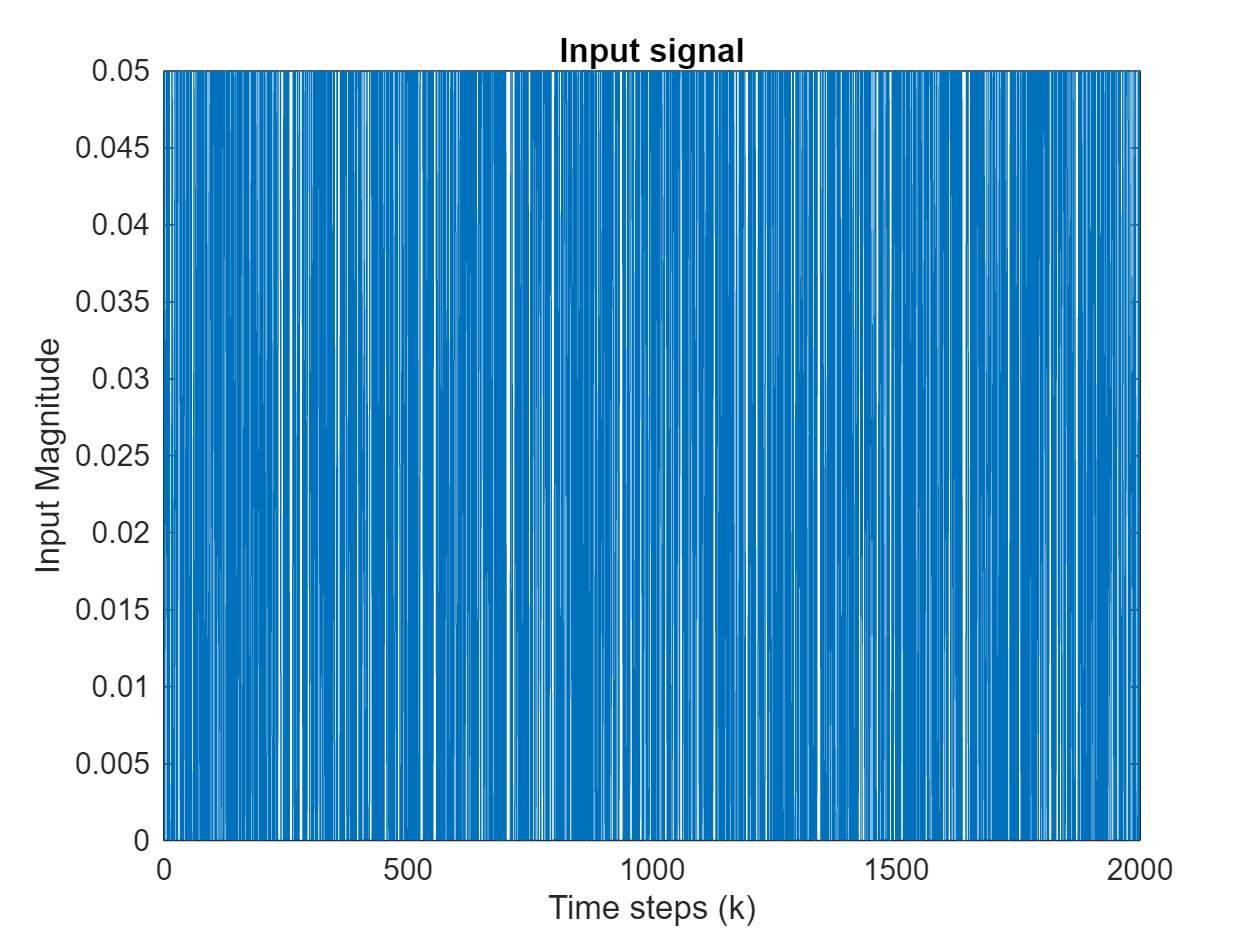

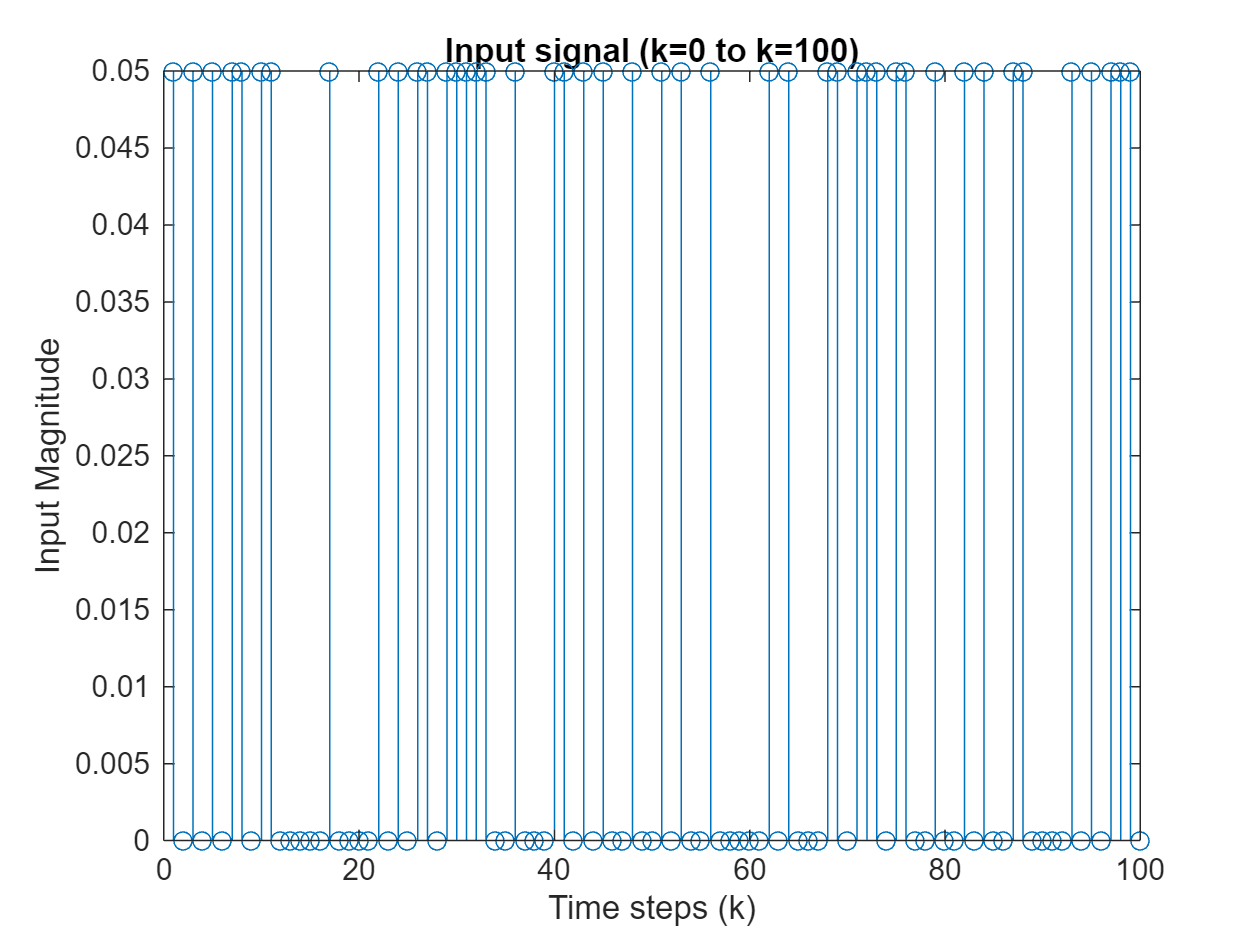

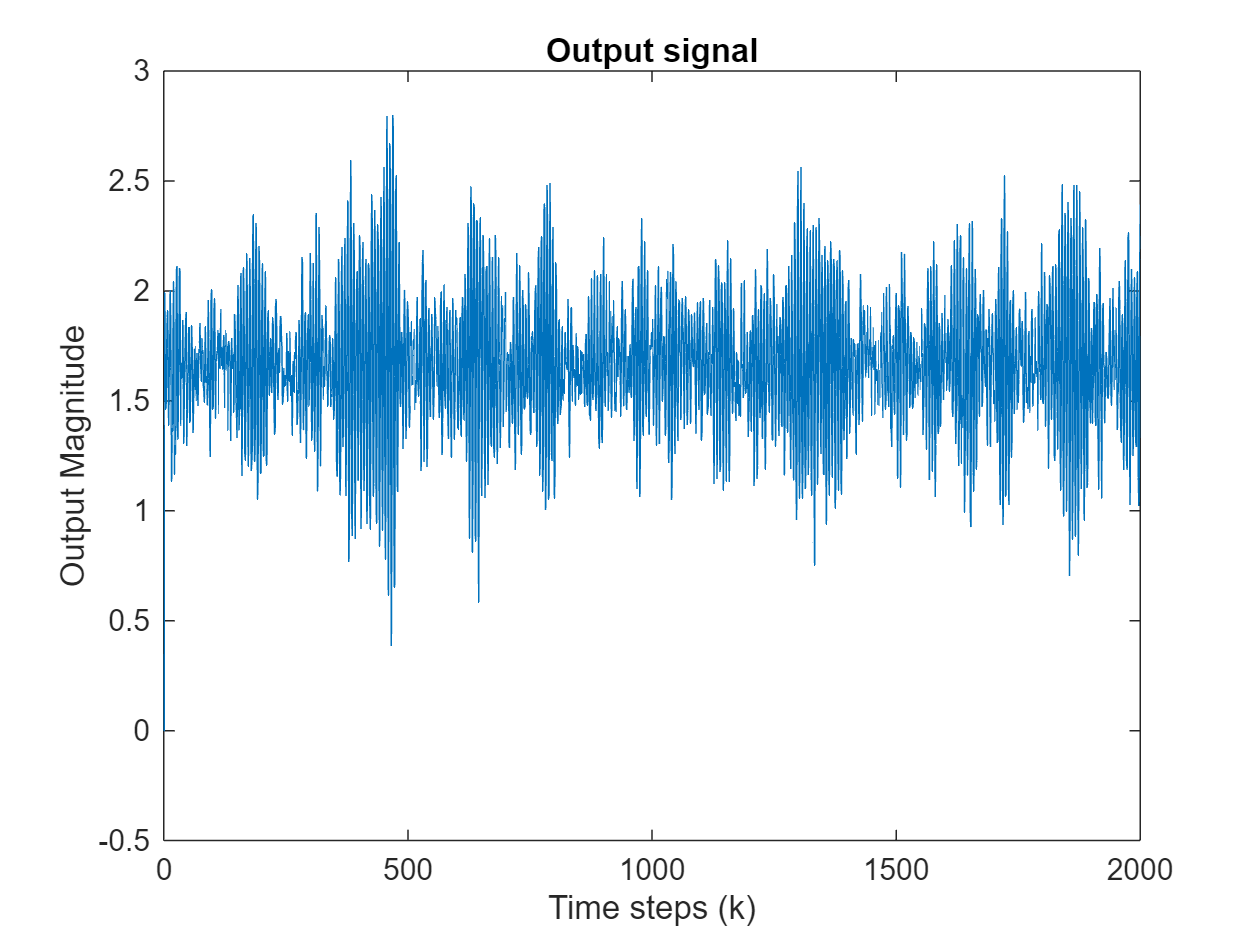

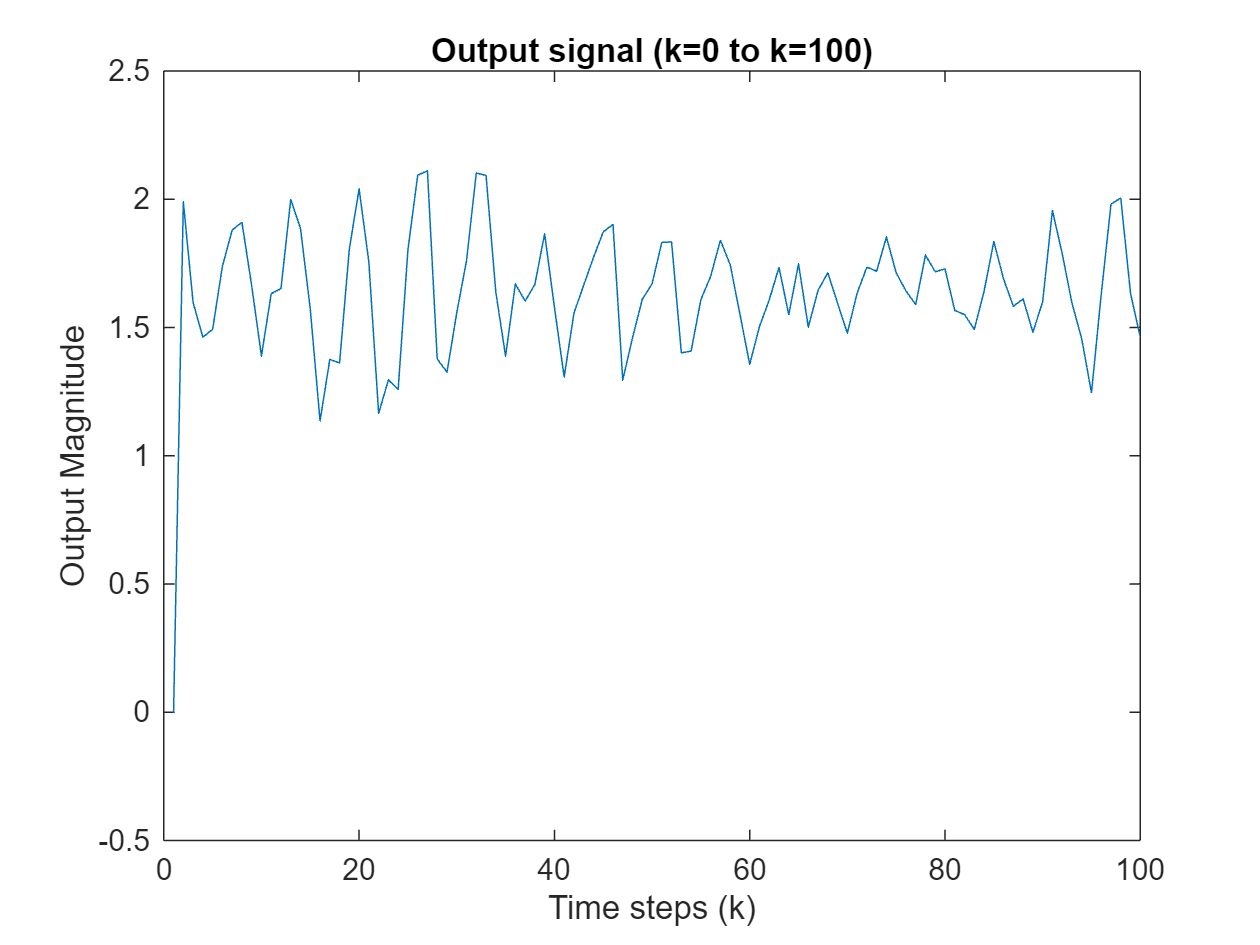

% Plot input signal
plot_input_output_signals(u, y)

The input signal is (TODO: note input signal type) with those properties (TODO: note properties). (TODO: After analysis of the impulse response, we can deduce that an integrator is implemented because it does not come back to zero.)

### 1.2 Determine Periodicity

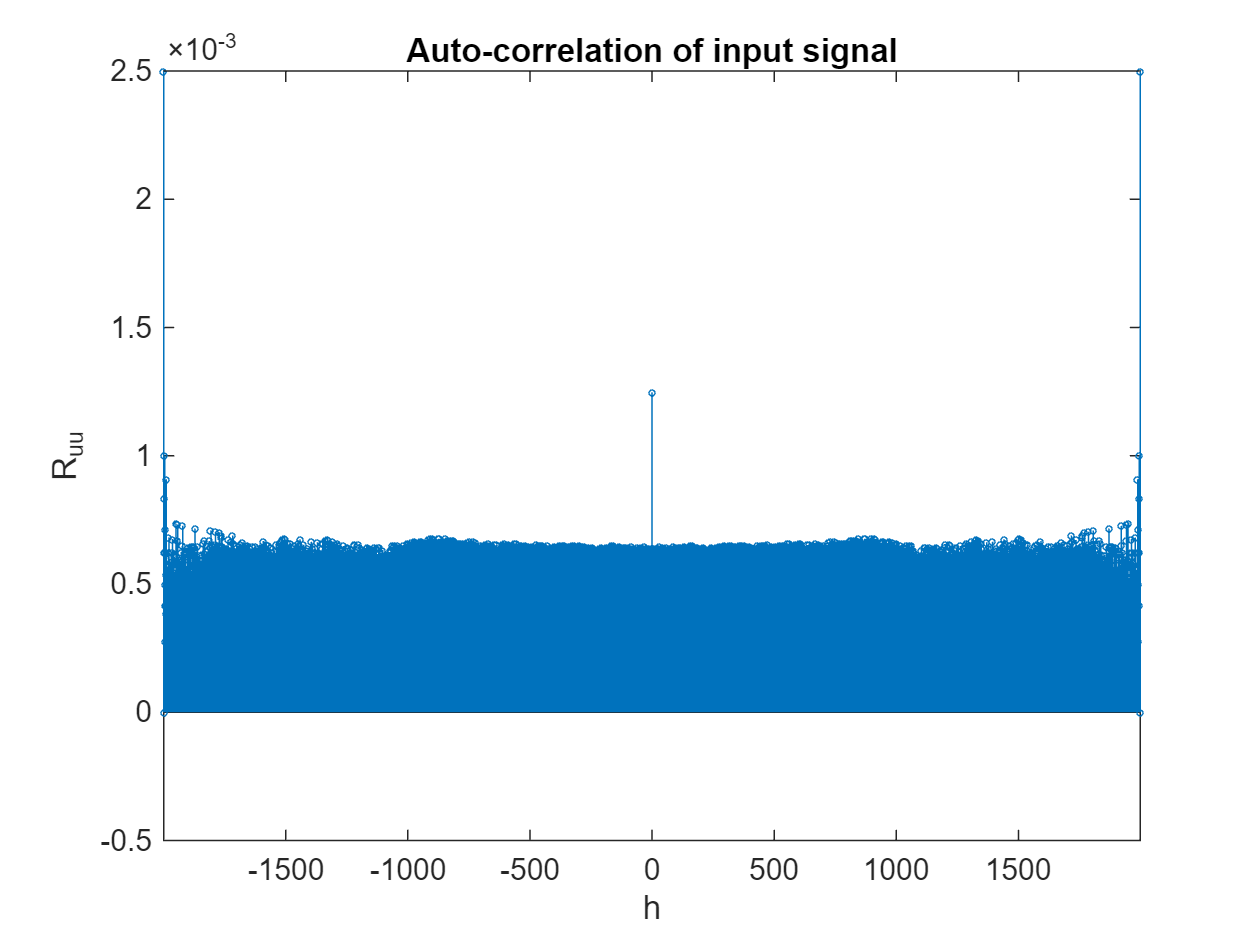

% If signal is periodic
% [R_result, h_result] = intcor(u,u); 
% figure;
% stem(h_result, R_result, 'MarkerSize', 2)
% xlabel('h')
% ylabel('R_{uu}')
% xlim([min(h_result), max(h_result)])
% title("Auto-correlation of input signal")

% If signal is not periodic. Unbiased is 
% usually preferred unless signals are 
% uncorrelated for big h.
R_result = xcorr(u, u, "unbiased")';
h_result = [flip(-1 * linspace(1, round(length(R_result)/2)-1, round(length(R_result)/2)-1)), linspace(0, round(length(R_result)/2)-1, round(length(R_result)/2))];
figure;
stem(h_result, R_result, 'MarkerSize', 2)
xlabel('h')
ylabel('R_{uu}')
xlim([min(h_result), max(h_result)])
title("Auto-correlation of input signal")

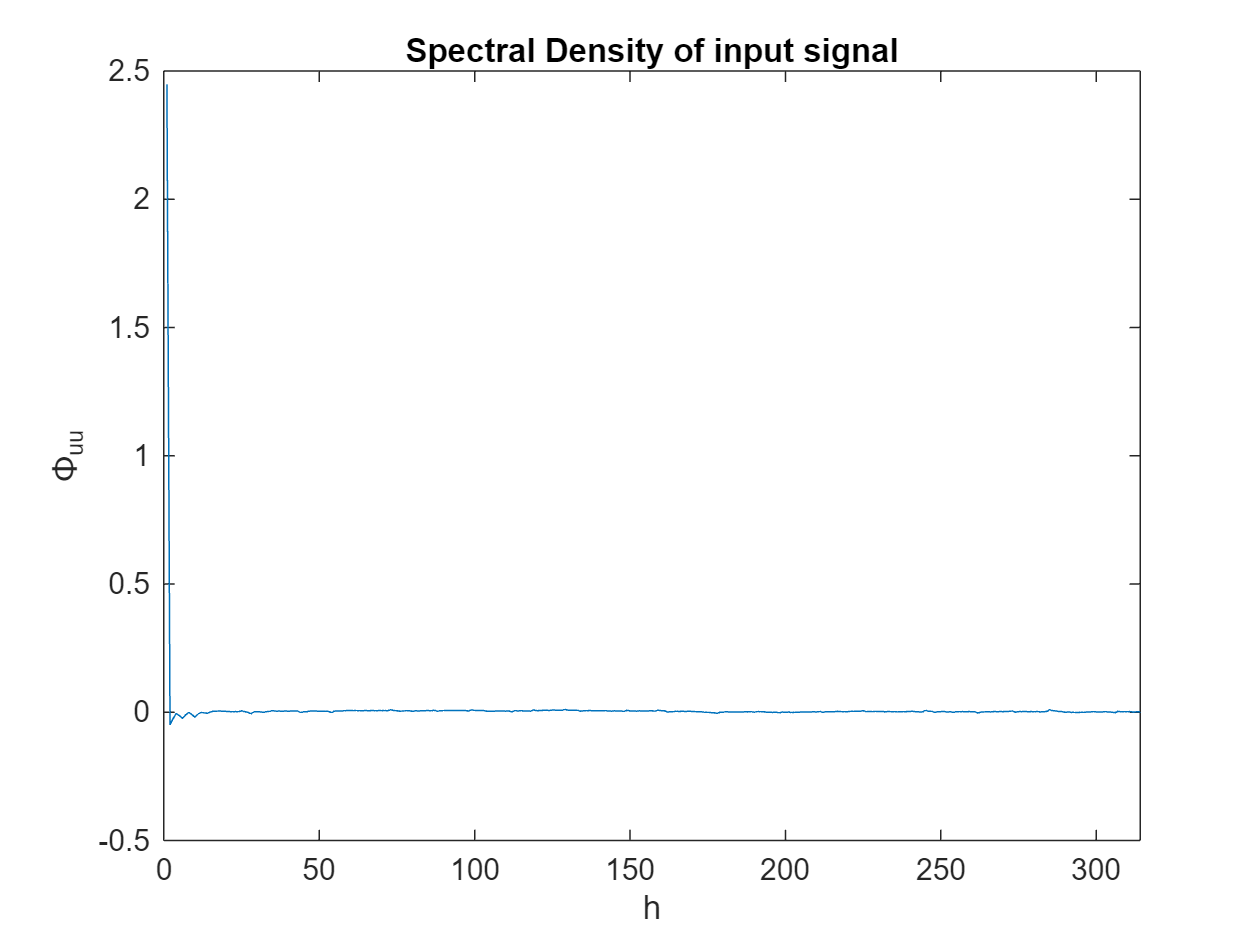


% Plot Spectral density of u
figure;
plot(real(fft(R_result)), 'MarkerSize', 2)
xlabel('h')
ylabel('\Phi_{uu}')
xlim([0, 2*pi/Ts])
title("Spectral Density of input signal")


% Count the number of peaks (number of periods)
[peaks, locs] = findpeaks(R_result(1:N+1), 'MinPeakHeight', 100);

nb_periods = length(peaks)

nb_periods = 0

T_u = N/nb_periods

T_u = Inf

The signal is periodic with a period of (TODO: add period). To determine this period, analysis of the auto-correlation was made. Note that if the signal is periodic, the function intcor can be used instead of xcor. 

intcor: if signal is periodic, because the esimate of the auto-correlation function is exactly the one for an infinite signal (reconstructed from the period).

xcorr: if the signal is not periodic, we need to approximate the auto-correlation function. We can use an unbiased estimate or a biased estimate. The unbiased is usually preferred, but for uncorrelated signals, biased estimate can be used (assumption on the values converging to 0 is fine in this case).

unbiased --> no bias, big variance

biased --> bad bias, variance converges to 0

### 1.3 Remove DC and Detrend data

% Detrend the data
% If no poles at 0
Z = detrend(iddata(y, u, Ts, "Period", T_u)); 

% If one pole at 0
% y_derivative = lsim(1 - tf('z', Ts)^-1, y);
% Z = detrend(iddata(y_derivative, u, Ts, "Period", T_u));

To remove the offset and prepare the data for further analysis, the matlab function detrend on a iddata object is used. This allows use to get rid of any linear trend in the data, and keep a unique variable Z.

## 2. **Frequency Response Identification**

### **2.1 Identify Impulse Response**

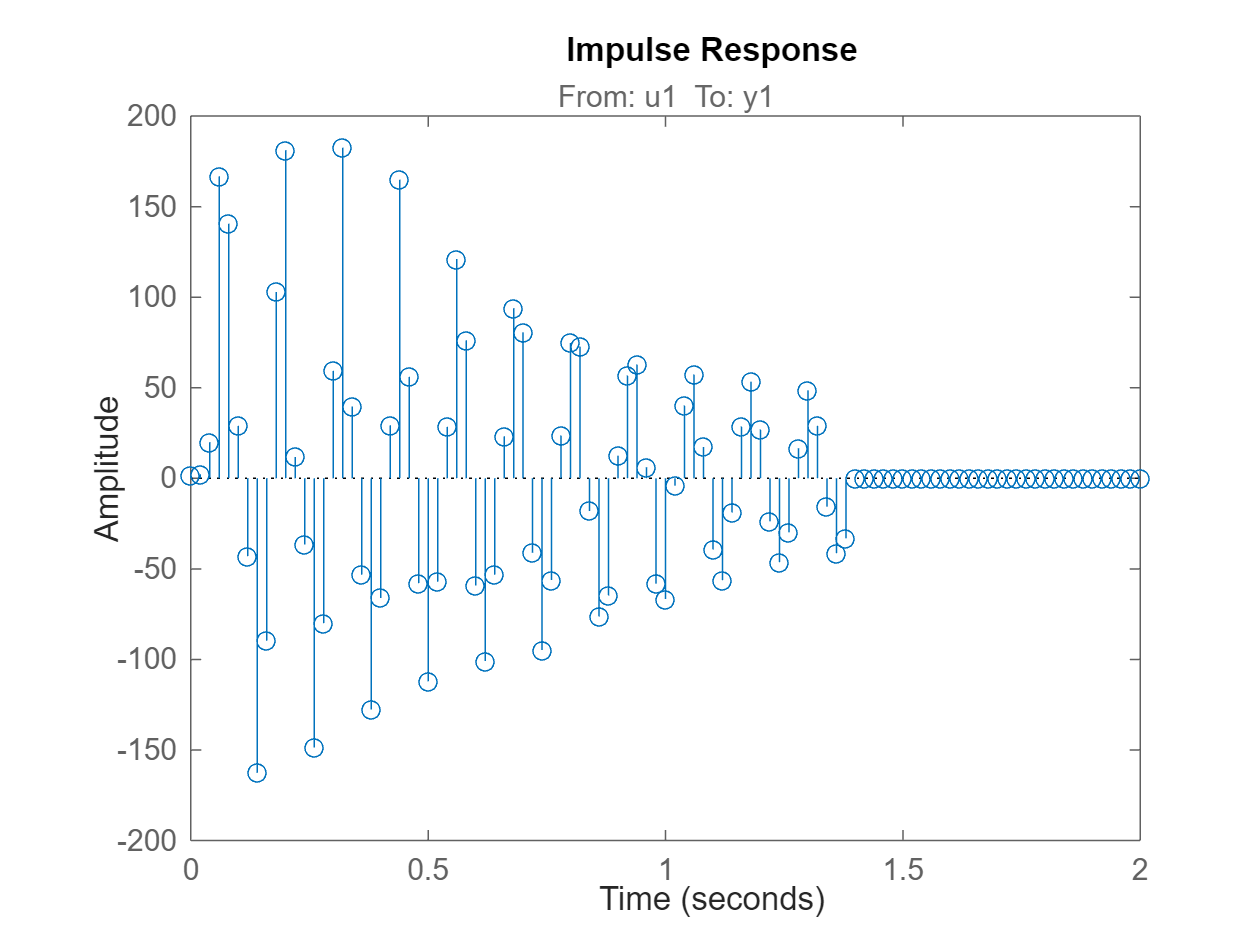

% Plot Impulse response
figure;
sys_impulseest = impulseest(Z);
impulseplot(sys_impulseest);

We need first to estimate the impulse response of the system using a FIR model. This will let us find a convenient window size in the spectral analysis later on, if needed. In addition, we can identify if the system has a pole at 0 (plant has an integrator), and therefore change the identification of the system to its derivative instead. Furthermore, we can validate if the system is stable or not. In our case:

% Find the size of the impulse response
impulse_response_size = 1.5; % Write result in seconds, directly from graph

### 2.2 Determine frequency response

% Define Options for Spectral Analysis
apply_windowing = false;
window_size = 4 * impulse_response_size / Ts ;
apply_averaging= true;
nb_avg_groups = 10;

% Run Spectral Anaylsis (from matlab)
frequency_response = spa_premium(Z, apply_windowing, window_size, apply_averaging, nb_avg_groups);

Performing Averaged Spectral Analysis with 10 groups of size 200...


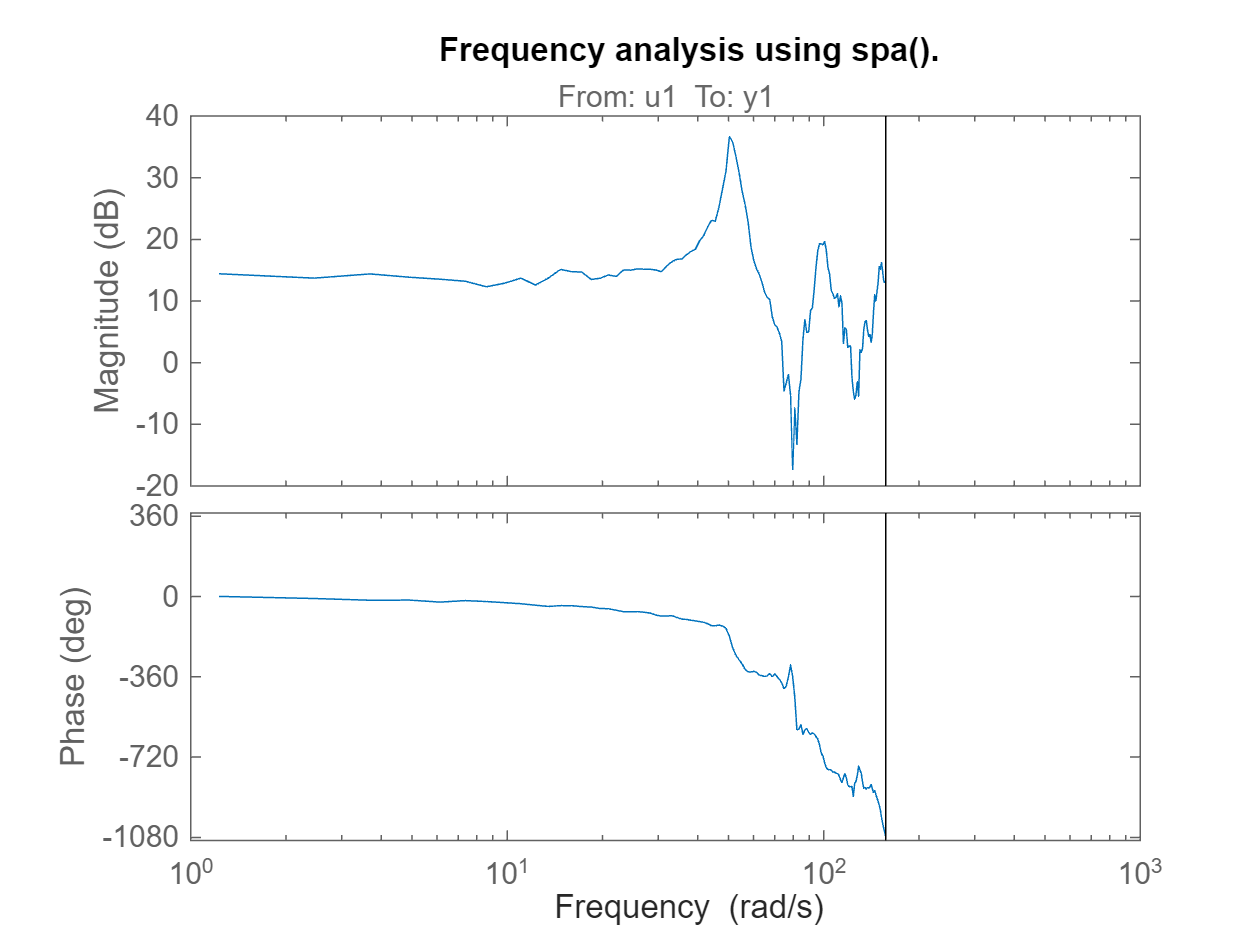


% Plot SPA Results
figure;
bode(frequency_response)
title("Frequency analysis using spa().")

#### 2.2.1 Basic Spectral Analysis (own)

% Choose auto-correlation function + biased/unbiased
Ruu = xcorr(Z.u, Z.u, 'biased');
Ryu = xcorr(Z.y, Z.u, 'biased');

Ruu = Ruu(1:N);
Ryu = Ryu(1:N);
Phi_uu = fft(Ruu);
Phi_yu = fft(Ryu);

G_spectral = Phi_yu ./ Phi_uu;

% frequency vector
N_tilda = length(Phi_uu);
omega_s = 2*pi/Ts;
omegas = 0:omega_s/N_tilda:(N_tilda-1)/N_tilda*omega_s;
omegas = omegas(omegas <= omega_s/2)

omegas =          0    0.1571    0.3142    0.4712    0.6283    0.7854    0.9425    1.0996    1.2566    1.4137    1.5708    1.7279    1.8850    2.0420    2.1991    2.3562    2.5133    2.6704    2.8274    2.9845    3.1416    3.2987    3.4558    3.6128    3.7699    3.9270    4.0841    4.2412    4.3982    4.5553    4.7124    4.8695    5.0265    5.1836    5.3407    5.4978    5.6549    5.8119    5.9690    6.1261    6.2832    6.4403    6.5973    6.7544    6.9115    7.0686    7.2257    7.3827    7.5398    7.6969


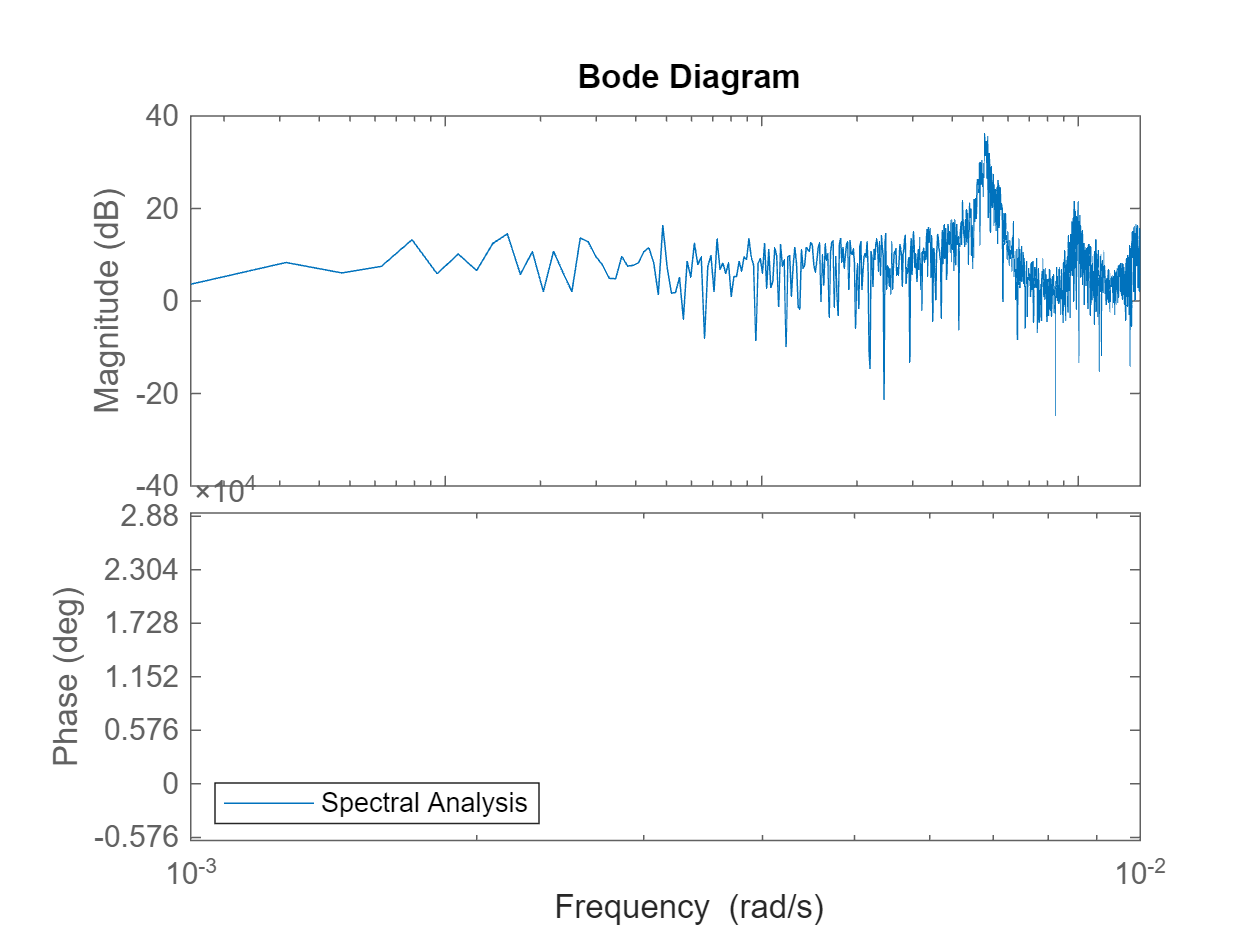

freq_domain_model = frd(transpose(G_spectral(1:length(omegas))), omegas);

figure; hold on;
bode(omegas, freq_domain_model)
legend(["Spectral Analysis"], 'Location', 'southwest')
xlim([0, Ts/2])
hold off;

#### 2.2.2 Windowed Spectral Analysis (own)

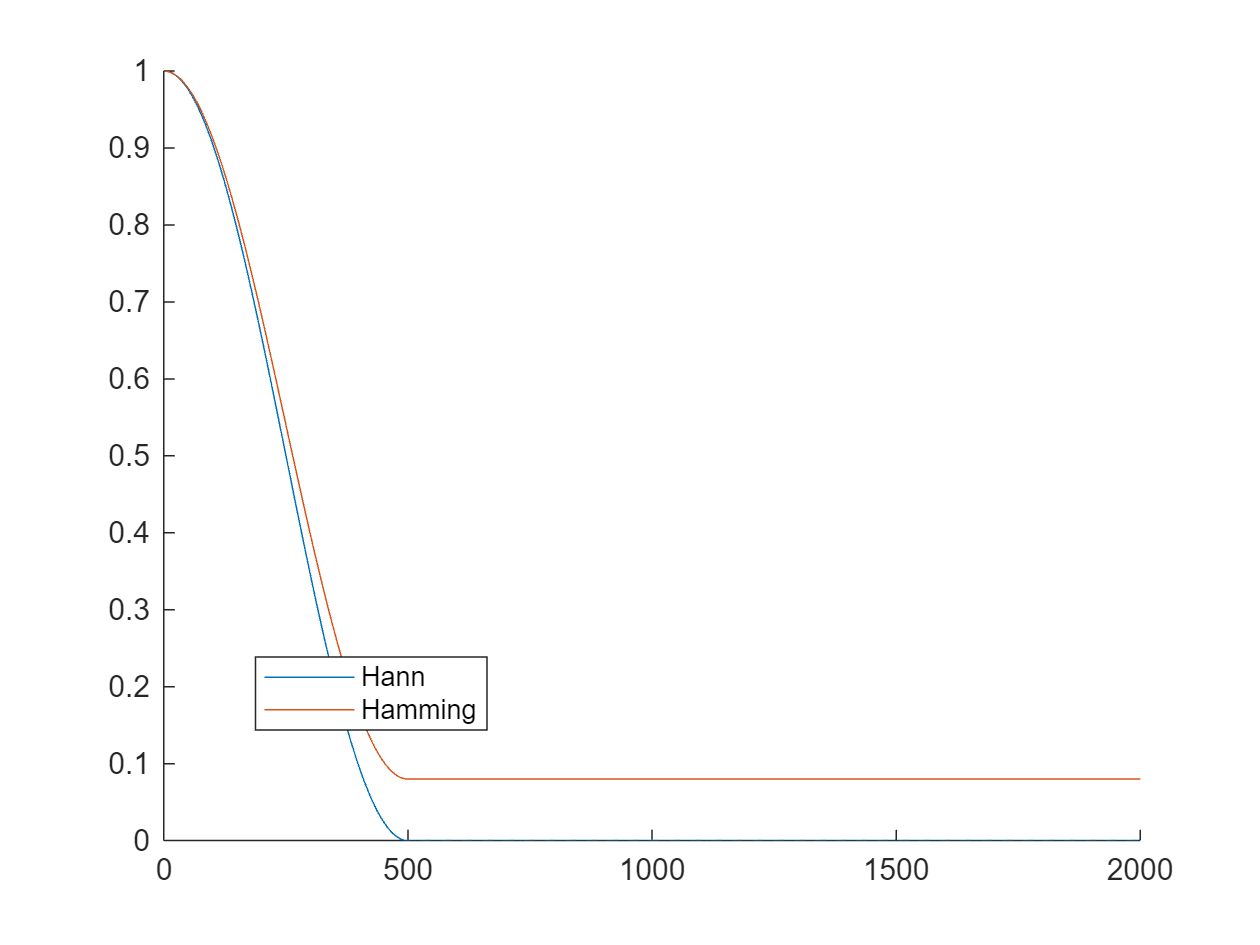

% Create window
window_size = N/2;
hann_window = hann(window_size);
hamming_window = hamming(window_size);

hann_window = hann_window(window_size/2+1:window_size);
hamming_window = hamming_window(window_size/2+1:window_size);
hann_window = [hann_window; zeros((N-window_size/2), 1)];
hamming_window = [hamming_window; hamming_window(end)*ones((N-window_size/2), 1)];

% Plot windows
figure; hold on;
plot(hann_window)
plot(hamming_window)
legend(["Hann" "Hamming"])
xlim([0, N]);
hold off;

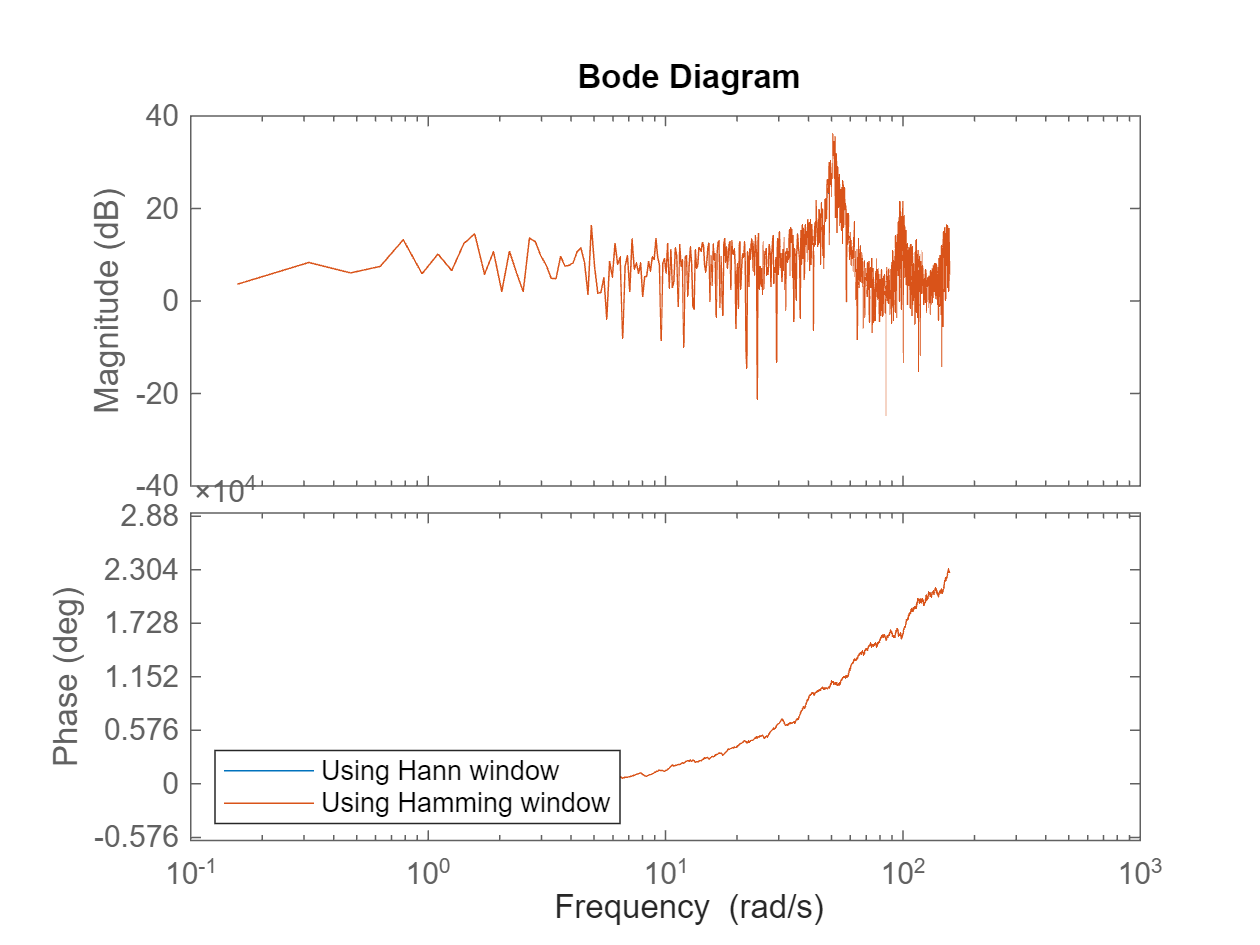


% Windowing with Hann
Ruu_w_hann = Ruu .* hann_window';
Ryu_w_hann = Ryu .* hann_window';
Phi_uu_w_hann = fft(Ruu_w_hann);
Phi_yu_w_hann = fft(Ryu_w_hann);

% Windowing with Hamming
Ruu_w_hamming = Ruu .* hamming_window';
Ryu_w_hamming = Ryu .* hamming_window';
Phi_uu_w_hamming = fft(Ruu_w_hamming);
Phi_yu_w_hamming = fft(Ryu_w_hamming);

% Compute constructed transfer functions
G_spectral_w_hann = Phi_yu_w_hann ./ Phi_uu_w_hann;
G_spectral_w_hamming = Phi_yu_w_hamming ./ Phi_uu_w_hamming;

% frequency vector
omega_s = 2*pi/Ts;
omegas = 0:omega_s/N:(N-1)/N*omega_s;
omegas = omegas(omegas <= omega_s/2);
freq_domain_model_w_hann = frd(transpose(G_spectral_w_hann(1:length(omegas))), omegas);
freq_domain_model_w_hamming = frd(transpose(G_spectral_w_hamming(1:length(omegas))), omegas);

% Plotting results
figure; hold on;
bode(freq_domain_model_w_hann)
bode(freq_domain_model_w_hamming)
legend(["Using Hann window" "Using Hamming window"], 'Location', 'southwest')
hold off;

#### 2.2.3 Average Spectral Analysis (own)

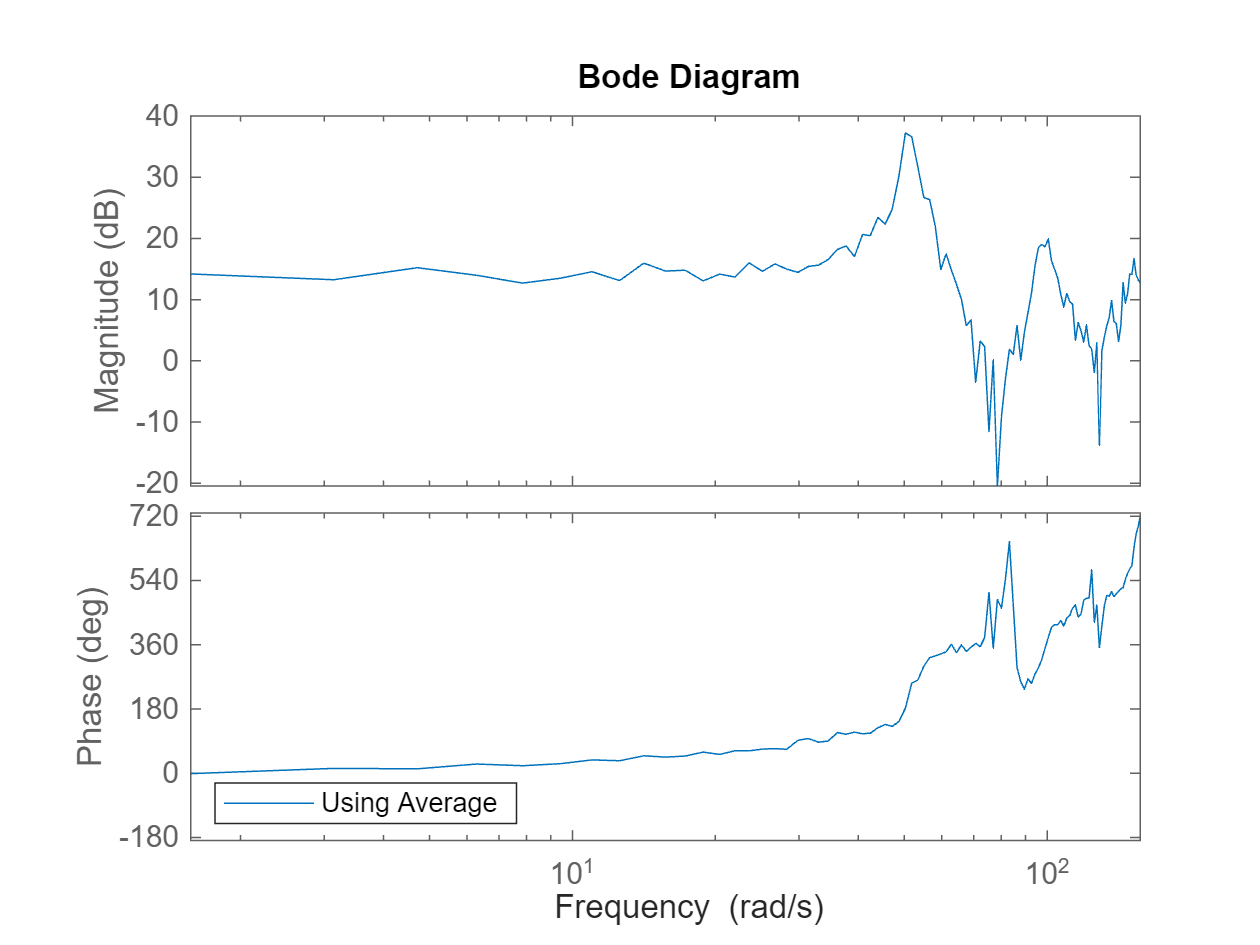

% Define number of subsets m
m = 10;

% Divide data in m sets
UU = [];
YY = [];
for i = 0:m-1
    U_k = Z.u(i*N/m + 1 : (i+1)*N/m);
    Y_k = Z.y(i*N/m + 1 : (i+1)*N/m);
    UU = [UU, U_k];
    YY = [YY, Y_k];
end

% Compute intercorrelation and autocorrelation for each set
RR_uu = [];
RR_yu = [];
for k = 1:m
    R_uu_k = intcor(UU(:, k), UU(:, k))';
    R_yu_k = intcor(YY(:, k), UU(:, k))';
    RR_uu = [RR_uu, R_uu_k(1:N/m)];
    RR_yu = [RR_yu, R_yu_k(1:N/m)];
end

% Compute average of Ruu and Ryu
Ruu_avg = zeros(N/m, 1);
Ryu_avg = zeros(N/m, 1);
for i = 1:m
    Ruu_avg = Ruu_avg + RR_uu(:, i);
    Ryu_avg = Ryu_avg + RR_yu(:, i);
end
Ruu_avg = Ruu_avg/m;
Ryu_avg = Ryu_avg/m;

% Compute Phis (fourrier transform of Ruu and Ryu)
Phi_uu_avg = fft(Ruu_avg);
Phi_yu_avg = fft(Ryu_avg);

% Compute constructed transfer function
G_spectral_avg = Phi_yu_avg ./ Phi_uu_avg;

% frequency vector
omega_nyquist = pi/Ts;
omega_s = 2*pi/Ts;
omegas = 0:omega_s/(N/m):(N/m-1)/(N/m)*omega_s;
omegas = omegas(omegas <= omega_nyquist);
freq_domain_model_avg = frd(transpose(G_spectral_avg(1:length(omegas))), omegas);

% Plotting Results
figure; hold on;
bode(freq_domain_model_avg, omegas)
legend(["Using Average"], 'Location', 'southwest')
hold off;

Before anything, we need to determine the frequency response of the system with a non-parametric model. To do so, we use spectral analysis. Indeed this method is adapted for random signals, but if the signal is periodic, using spectral analysis give the same results as Fourier. The spectral analysis can be improved with a Hann window, or over averaging. To guarantee good results, we use our own spectral analysis code as well as the spa matlab function to validate it. Also, this will confirm our prior belief on the existance of a pole at origin, determined from the impulse response. Indeed, there is (TODO: add if pole exist of not).

The use of Hann/Hamming window on correlation function is adapted with a length of (TODO_len window) in order to adapt to the size of the data. A good way to find the window size is to make it bigger than the settling time of the impulse response of the signal (determined here above). Note that a large window size will smoothen the model, and that a small show small improvement compared to a classic spectral analysis. The goal is to find a suitable size such that the resonant peaks are kept, and that the noise is eliminated.

For averaging, the input signal is separated in (TODO: partition du signal) and the averaging is performed on the spectral density functions. Then the transfer function can be found.

## **3: System strucure and order estimation:**

### 3.1 Order Estimation

#### 3.1.1 Frequency response

Since the slope of the frequency response is (TODO: add slope), the system must have at least (TODO: e.g., 20 dB/decade = 1 pole) pole(s). Additionally, we observe (TODO: number of peaks) resonance peak(s), each corresponding to a pair of complex conjugate poles. Therefore, the total number of poles is at least (TODO: minimum number of poles). This estimation gives a rough idea of the order of the system, and ought to be considered as a lower bound.

#### 3.1.2 Loss function

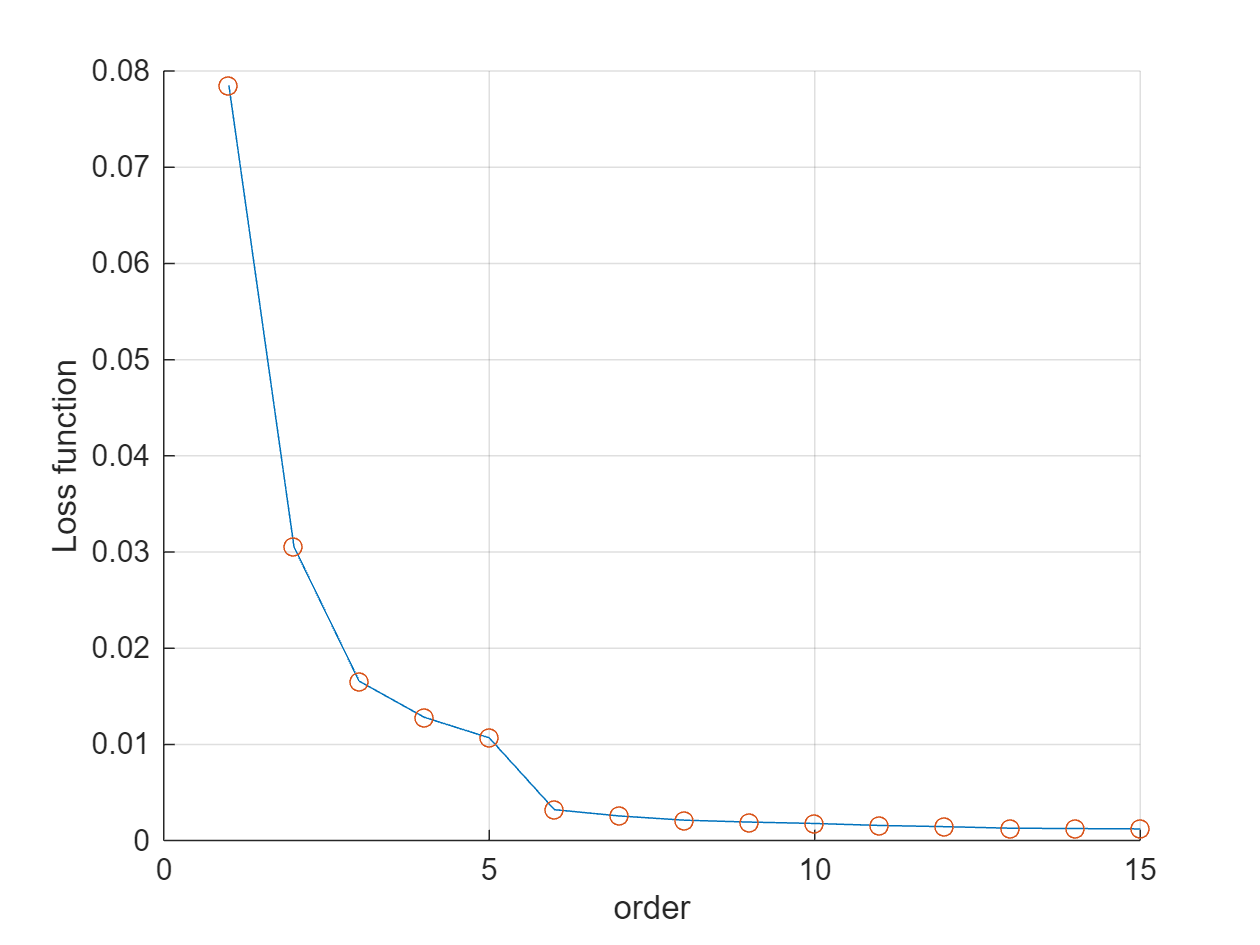

% Loss Functions for increasing order
nk = 1;
LossFuncs = [];
for delta = 1:15
    na = delta;
    nb = delta;
    M = arx(Z, [na, nb, nk]);
    LossFuncs = [LossFuncs, M.EstimationInfo.LossFcn];
end

% Plotting
figure; hold on;
plot(LossFuncs)
scatter(linspace(1, 15, 15), LossFuncs)
xlabel("order")
ylabel("Loss function")
grid on;
hold off;

The analysis of the loss function estimation can provide an idea on what is the number of poles. The loss function is supposed to decrease only a little for the true model. From the plot we can deduce that the number of poles is between (TODO: x and y poles), since the rough elbow shape sits in this interval.

#### 3.1.3 Zero-Pole cancellation

Order 3:

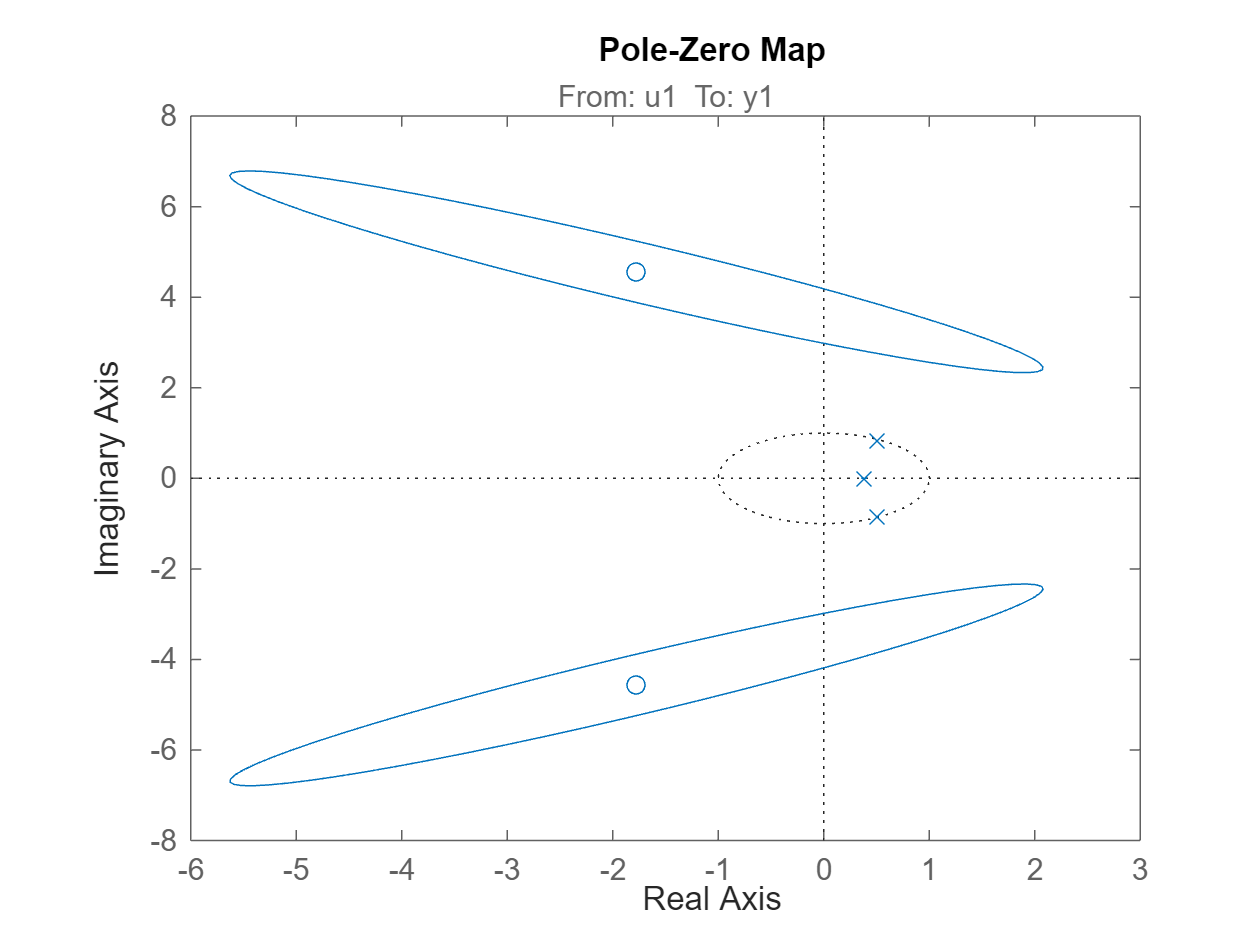

Order 4:

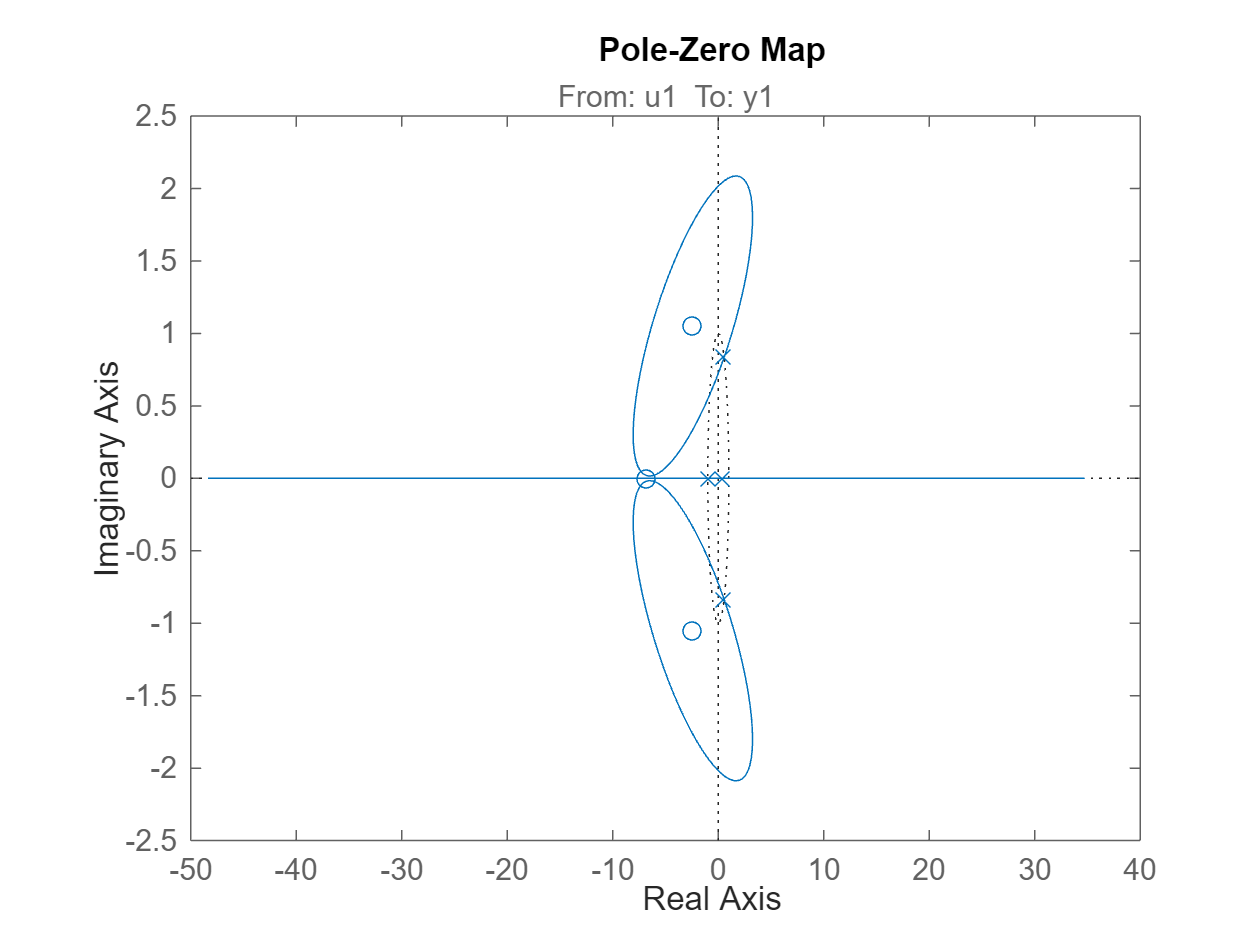

Order 5:

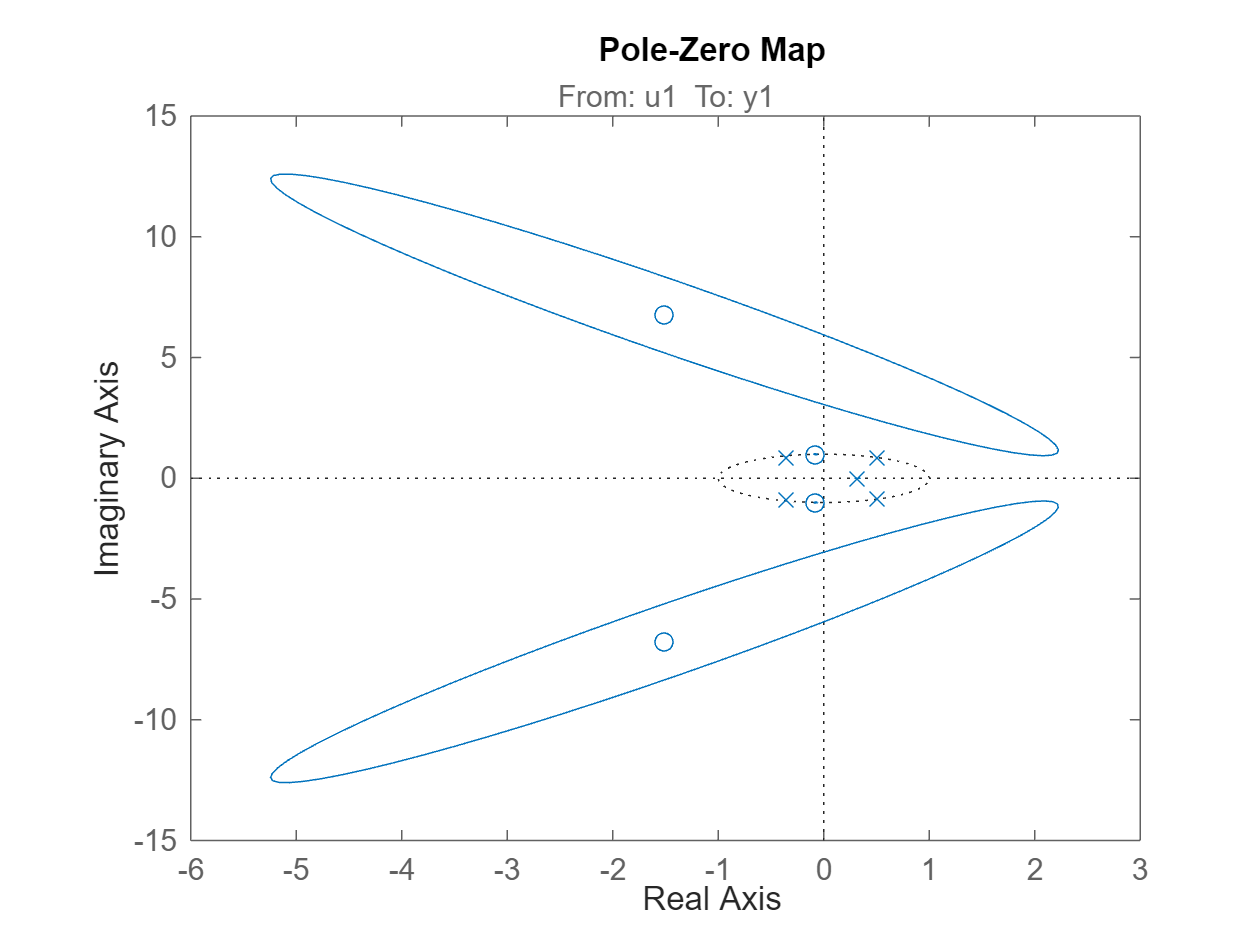

Order 6:

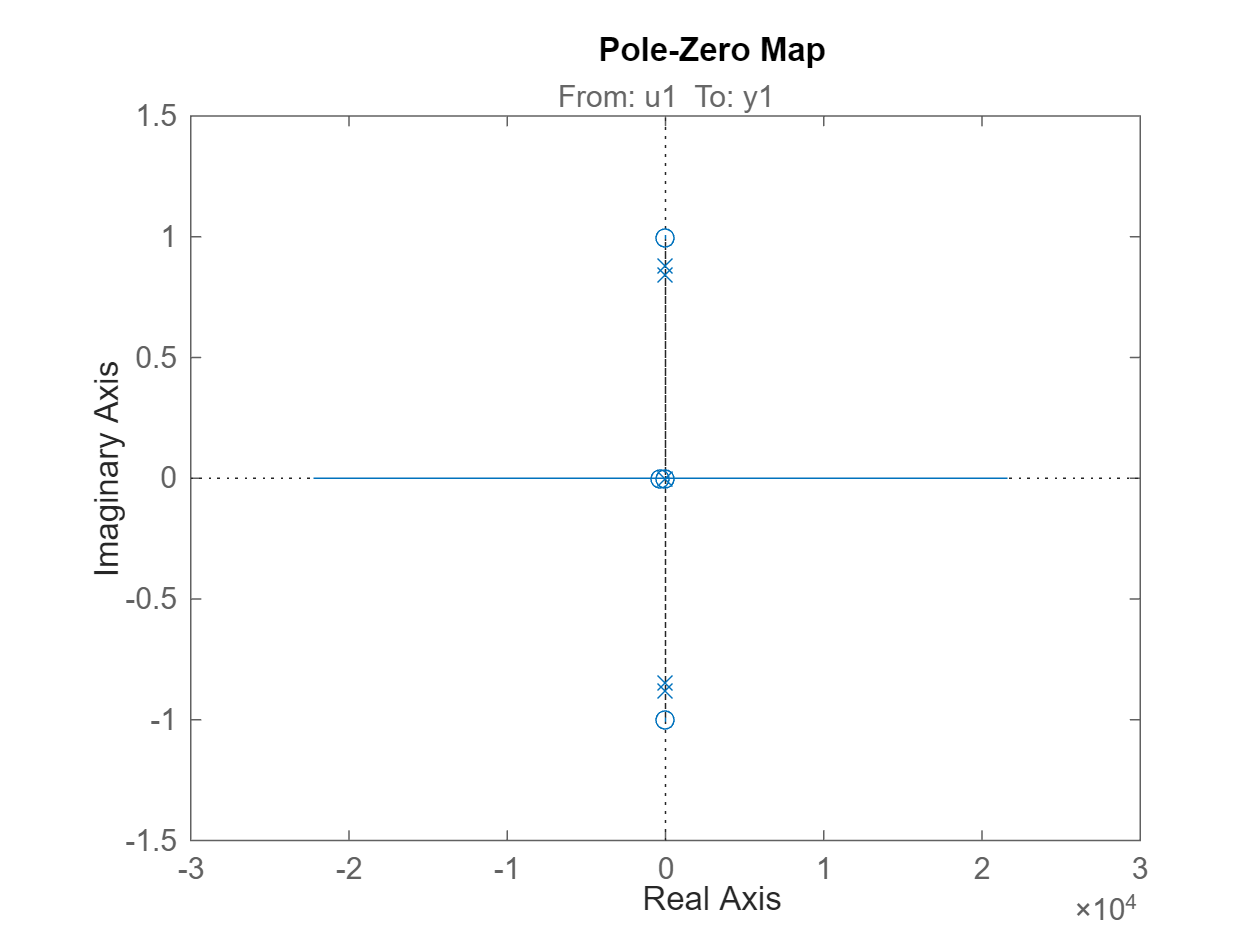

Order 7:

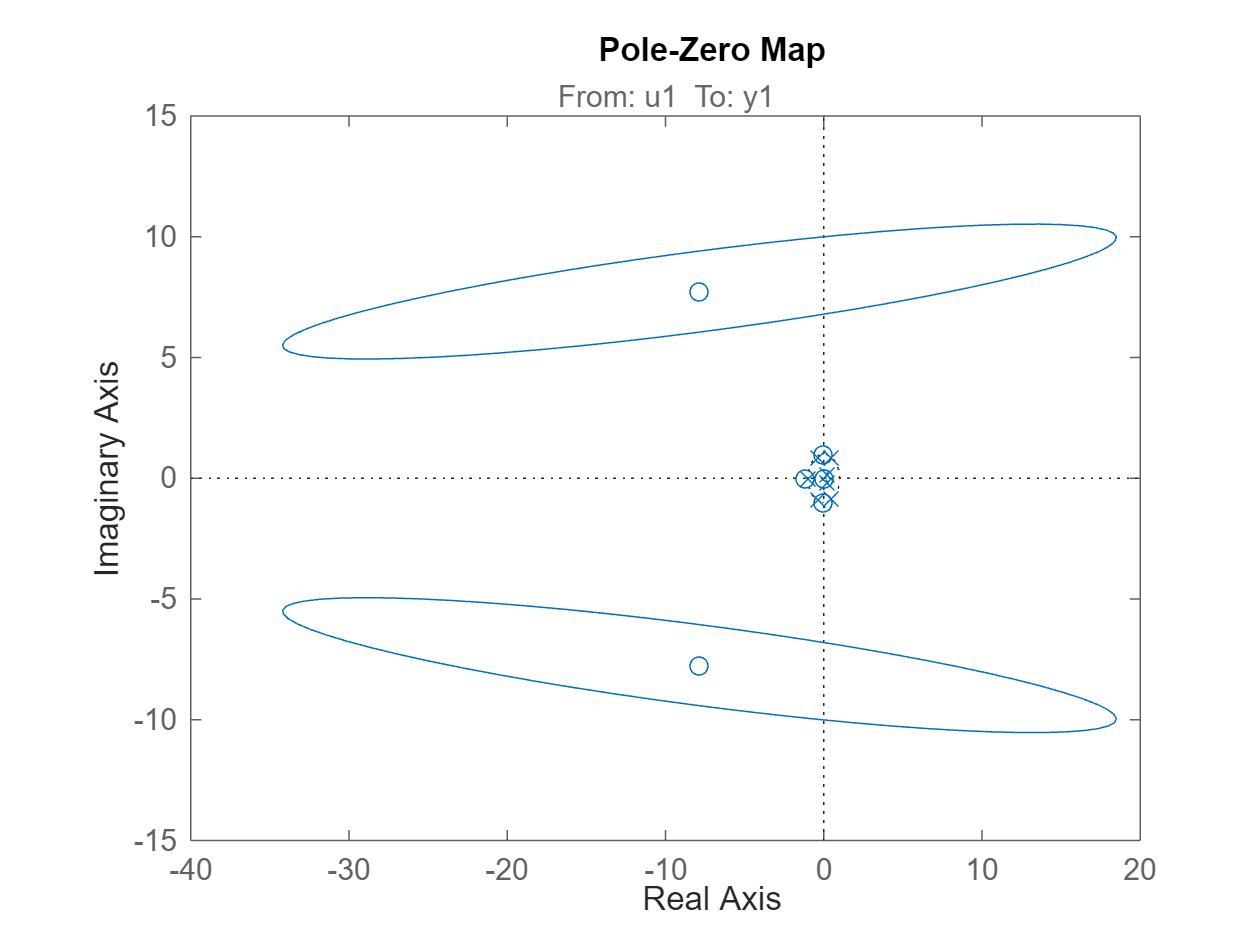

Order 8:

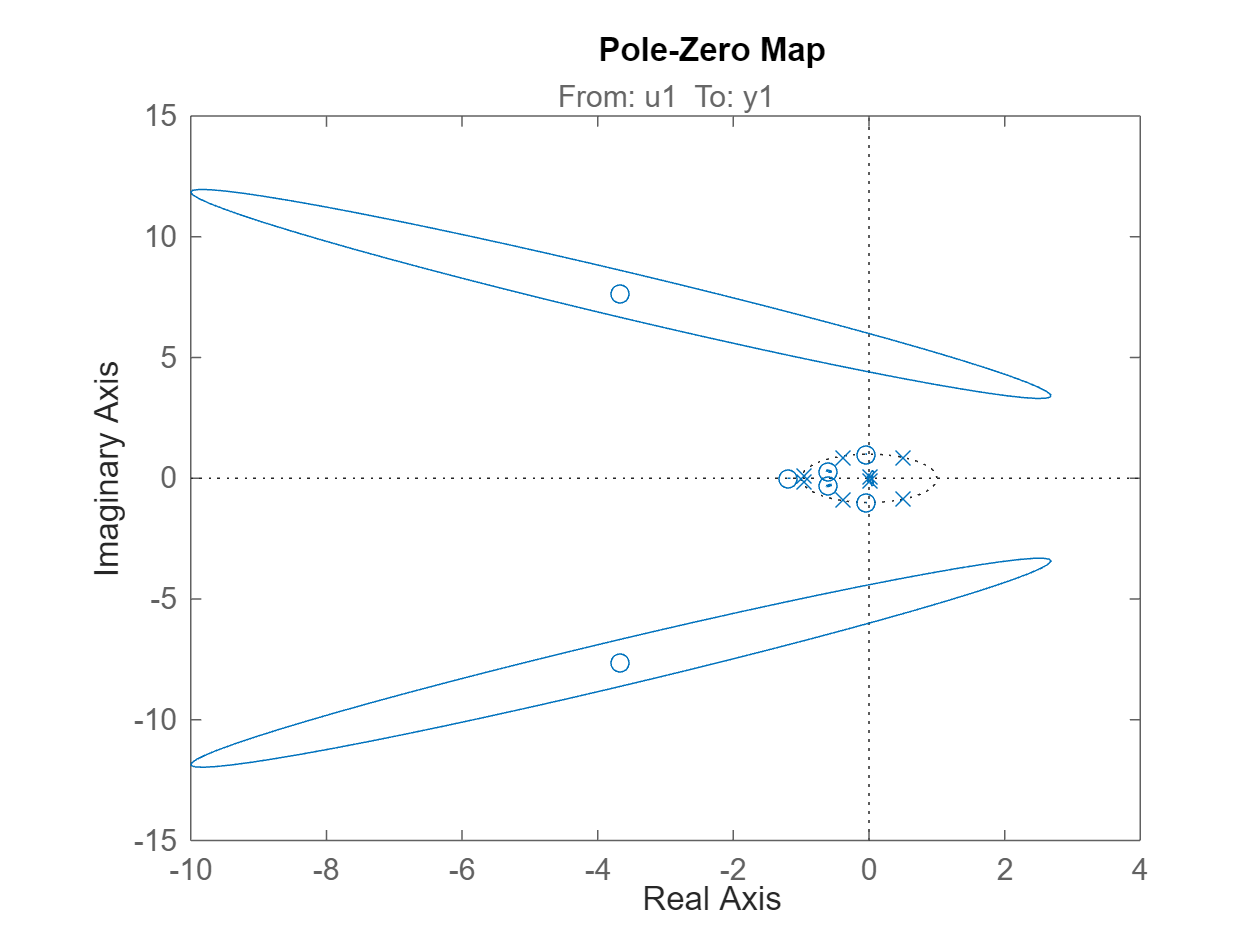

Order 9:

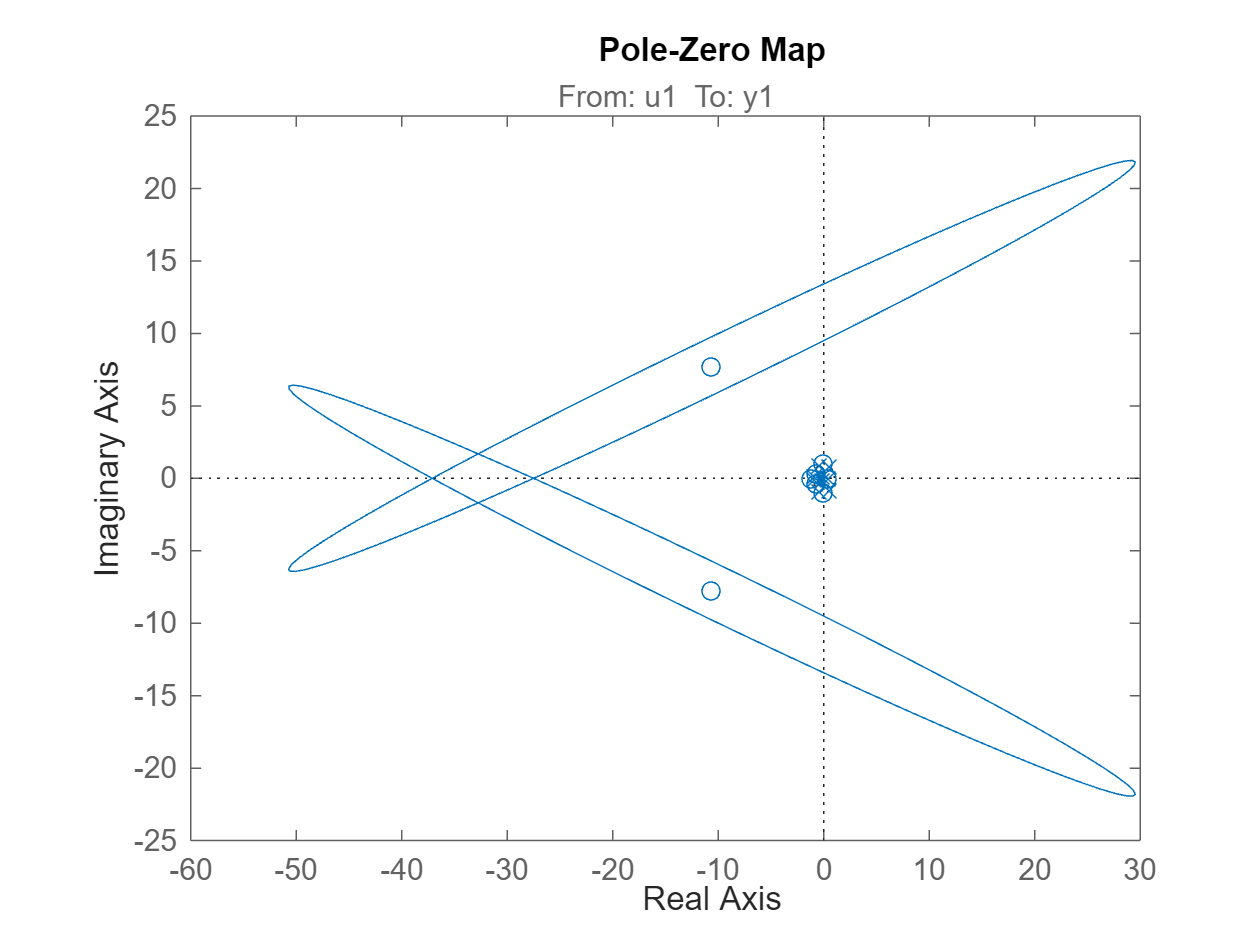

% Validate with Pole/Zero cancellation
delta_min = 3; % define nb max of poles
delta_max = 9; % define nb min of poles

nk = 1; %sans doute pas besoins de le changer à voir si le delai parait très différent
for delta = delta_min:delta_max
    na = delta;
    nb = delta;
    nc = delta;
    M = armax(Z, [na, nb, nc, nk]);
    fprintf("Order " + string(delta) + ":")
    figure;
    h = iopzplot(M);
    showConfidence(h,2);
end

From the previous estimation we can plot the pole zero map with different orders and see if there is a zero-pole cancellation. A pole/zero cancellation indicates an over estimation of the order of the system. From the following plots, we can deduce that the first pole cancels at (TODO: add order for first cancellation O_1), then the true order is supposed to be (TODO: True order is O_1 – 1, also add a picture).

#### 3.1.4 Rank of Q

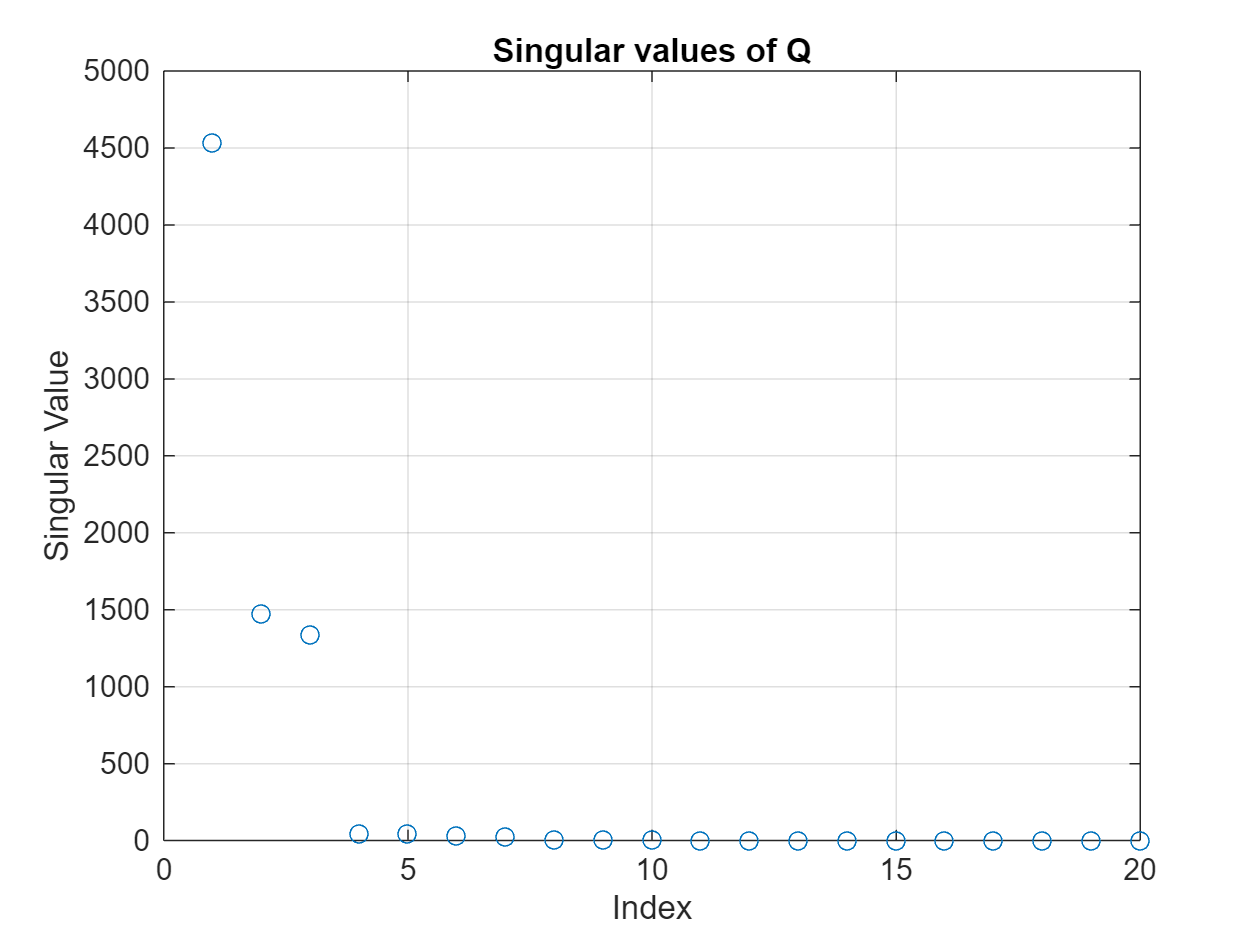

%Choisir r plus grand que l'ordre du systeme
r = 20;

%noise: activate intstrum:
instrum = true;
    
Y = [];
U = [];
PHI = [];

for k = 1:N-r+1
    %Construction of Y and U
    Y_r_k = y(k:k+r-1);
    U_r_k = u(k:k+r-1);

    Y = [Y, Y_r_k];
    U = [U, U_r_k];

    %for instrumental: construction of Phi
    phi_k = [u(k:k+r-1); y(k:k+r-1)];
    PHI = [PHI, phi_k];

end


U_ortho = eye(N-r+1) - U' * (U * U')^(-1) * U;
Q = Y * U_ortho;

%For noise calculation with Q
if instrum
    Q_hat = Q * PHI';
    [UU, S, V] = svd(Q_hat); 
%without noise
else
    [UU, S, V] = svd(Q);
end

% Plot the singular values of Q in order to define which 
% one is close to 0
figure;
sing_vals = diag(S);
plot(sing_vals, 'o'); grid on;
xlabel('Index'); ylabel('Singular Value');
title('Singular values of Q');


n = 2;

% Create observability matrix
O_r = UU(:, 1:n);

Another way to have an approximation of the order of the system is to create the double extended observability matrix, find its singular values and to deduce the order from the point that it becomes close to zero. In this case, we can say that the order should be between (TODO: add interval).

(TODO: Add picture of the svd of Q)

### 3.2 Delay estimation

% Estimate Delay
delta = 6;  % Estimated order

% Using FIR
d = 1;
m = d+delta;
phi = Z.u(d+1:m);
PHI = toeplitz(Z.u, [Z.u(1) zeros(1, (m-d-1))]);
Y = Z.y(d+1:m);
theta_hat = inv(PHI' * PHI) * PHI' * y;
Y_hat = PHI * theta_hat;
J_theta_hat = sum((Z.y-Y_hat).^2);
theta_hat'

ans =     0.0800    0.1545    0.4420    3.1878    2.7010    0.5541


estimate_2std = sqrt(diag((1/(N-m) * J_theta_hat) * pinv(phi * phi')))'

estimate_2std =     2.0094    2.0175    2.0094    2.0175    2.0094    2.0175



% Using ARMAX
M_ARMAX = armax(Z, [delta, delta, delta, d]);
display(M_ARMAX.b)

         0    0.0012    0.4060    3.4925    4.1661    3.8511    3.3464



display(M_ARMAX.db)

         0    0.0399    0.0415    0.0512    0.0645    0.0455    0.0559



Delay was estimated using ARMAX model and comparing B coefficient to its standard deviation. A FIR model can be used if the system is not oscillatory, because it is unbiased and uses the least-square algorithm. Seeing that (TODO: nb of coeff above zero: ) are zero, we can deduce that the delay is (TODO: estimated delay value).

(TODO: insert table with B coeff and B coeff std as picture)

### 3.3 Estimation of n and m

d_min = 0;
d_max = 3;
na_min = 1;
na_max = delta;
nb_min = 1;
nb_max = delta - d + 1;

% Validation with arxstruc
NN = struc(na_min:na_max, nb_min:nb_max, d_min:d_max);
M_arxstruc = arxstruc(u(1:length(u)/2), y(1:length(y)/2), u(length(u)/2:end), y(length(y)/2:end), NN);
arxstruc_results = selstruc(M_arxstruc, 0);
na = arxstruc_results(1)

na = 6

nb = arxstruc_results(2)

nb = 6

d = arxstruc_results(3)

d = 3

Using arxstruc with the previously deduced parameters, we can deduce the value of nb which is: (TODO: Add value of nb).

## 4. Model identification and validation

### 4.1 Split the data

% Divide Data in train and test sets
train_test_ratio = 0.7;
N = length(Z.y);
idx = floor(0.7 * N);

Z_train = Z(1:idx);
Z_validation = Z(idx+1:end);

We split the data between two sets, one for training and one to validate after. We choose a ratio of 70% of the data, which is suitable for such number of data.

### 4.2 Comparison with different parametric models

% Identify parametric models
%Change na and nb related to Arxstruct validation
na = 6;
nb = 5;
nc = na;
nd = na;
nk = 2;

% arx
M_arx = arx(Z_train, [na, nb, nk]);

% iv4
M_iv4 = iv4(Z_train, [na, nb, nk]);

% armax
M_armax = armax(Z_train, [na, nb, nc, nk]);

% oe
nf = na;
M_oe = oe(Z_train, [nb, nf, nk]);

% bj
M_bj = bj(Z_train, [nb, nc, nd, nf, nk]);

% n4sid
M_n4sid = n4sid(Z_train, delta);

### 4.3 Time-domain validation

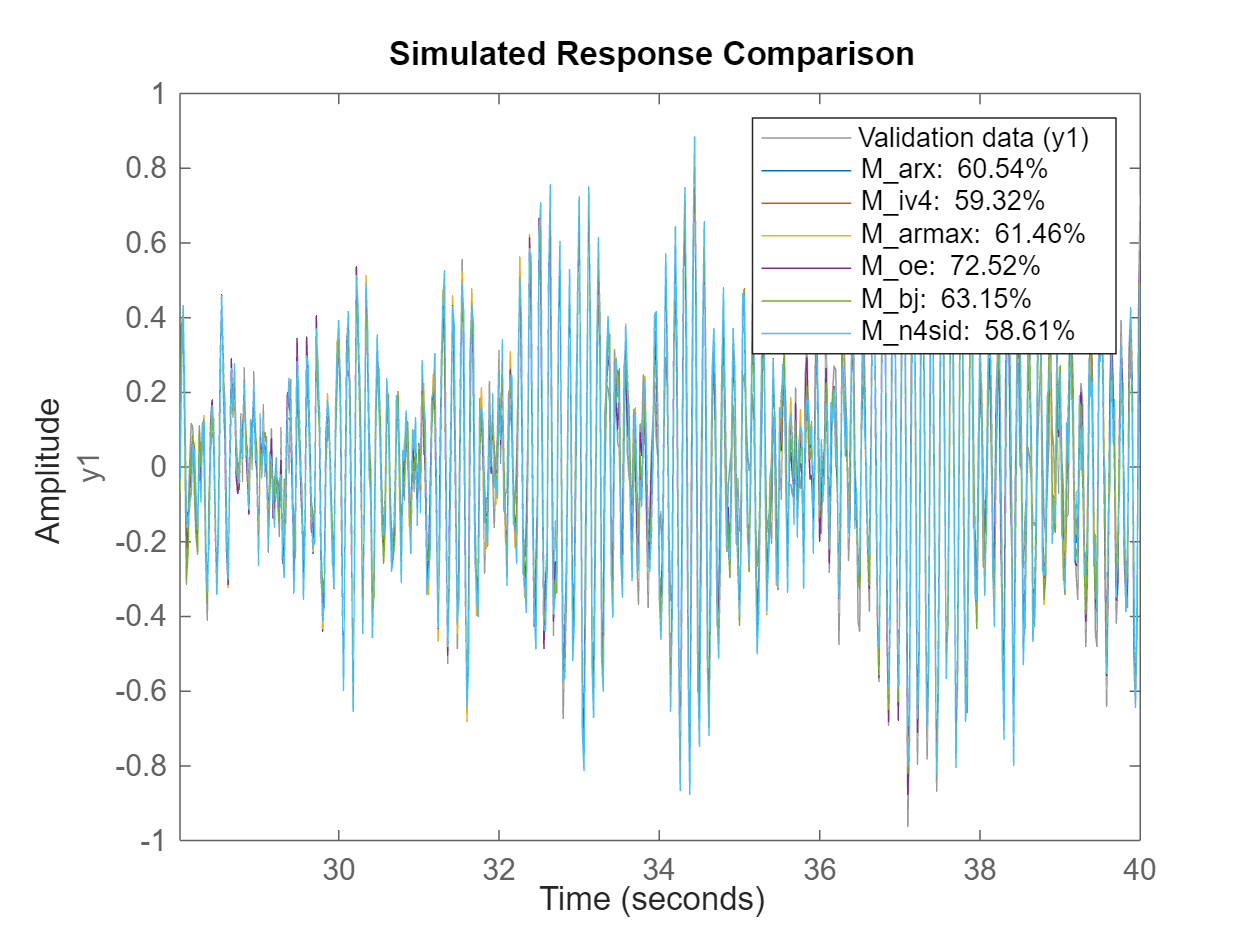

% Model Comparison
compare(Z_validation, M_arx, M_iv4, M_armax, M_oe, M_bj, M_n4sid)

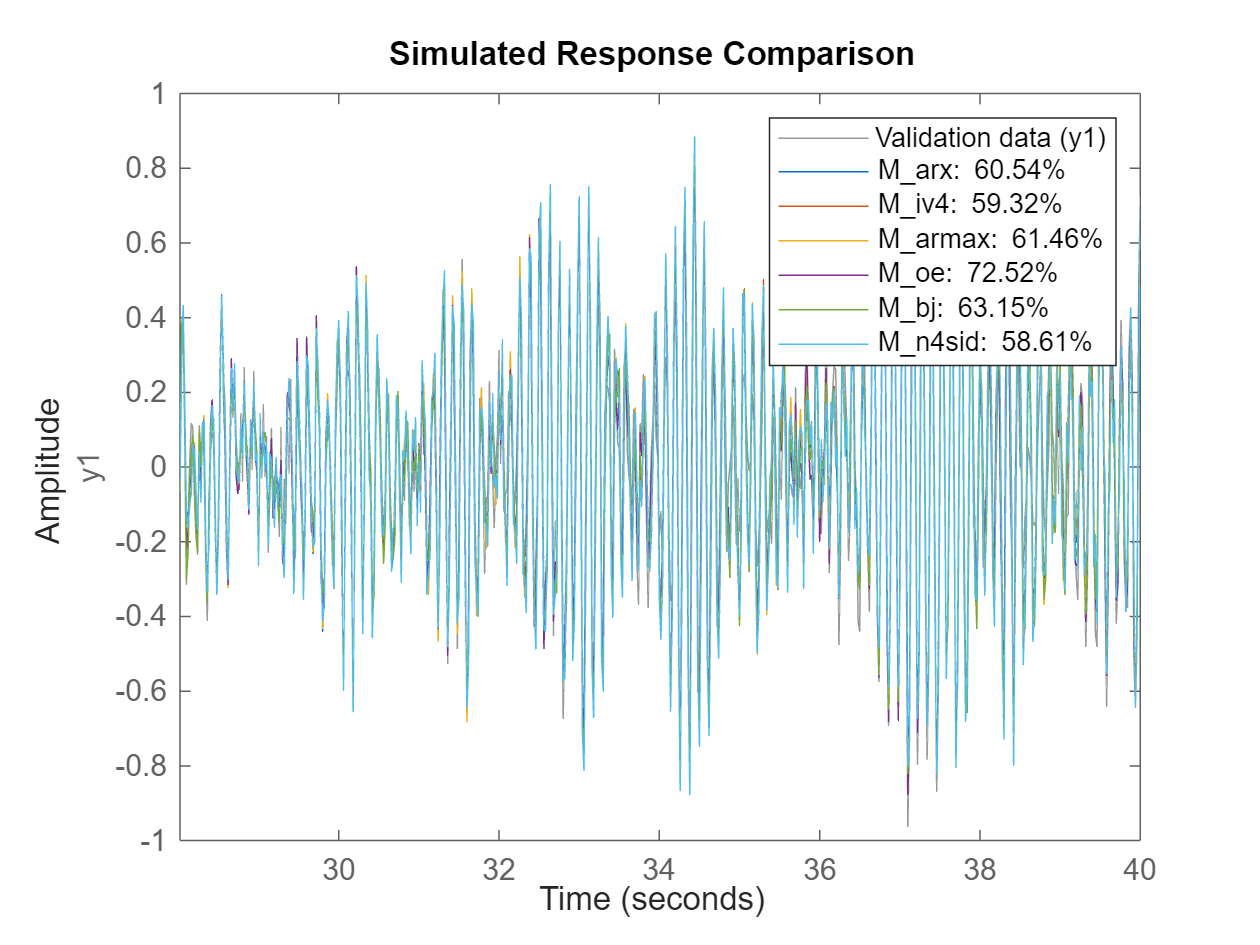

compare(Z_validation, M_arx, M_iv4, M_armax, M_oe, M_bj, M_n4sid)

To compare the model in the time domain, the function compare() is used generating the graph above. We can see that some models are better performing than others: (TODO add performing models). 

(TODO: add the graph of time domain valid)

(TODO: verify the fit on the graph with a zoom: fit of curve, delay, noise reproduction, fit criterion)

### 4.4 Frequency domain validation

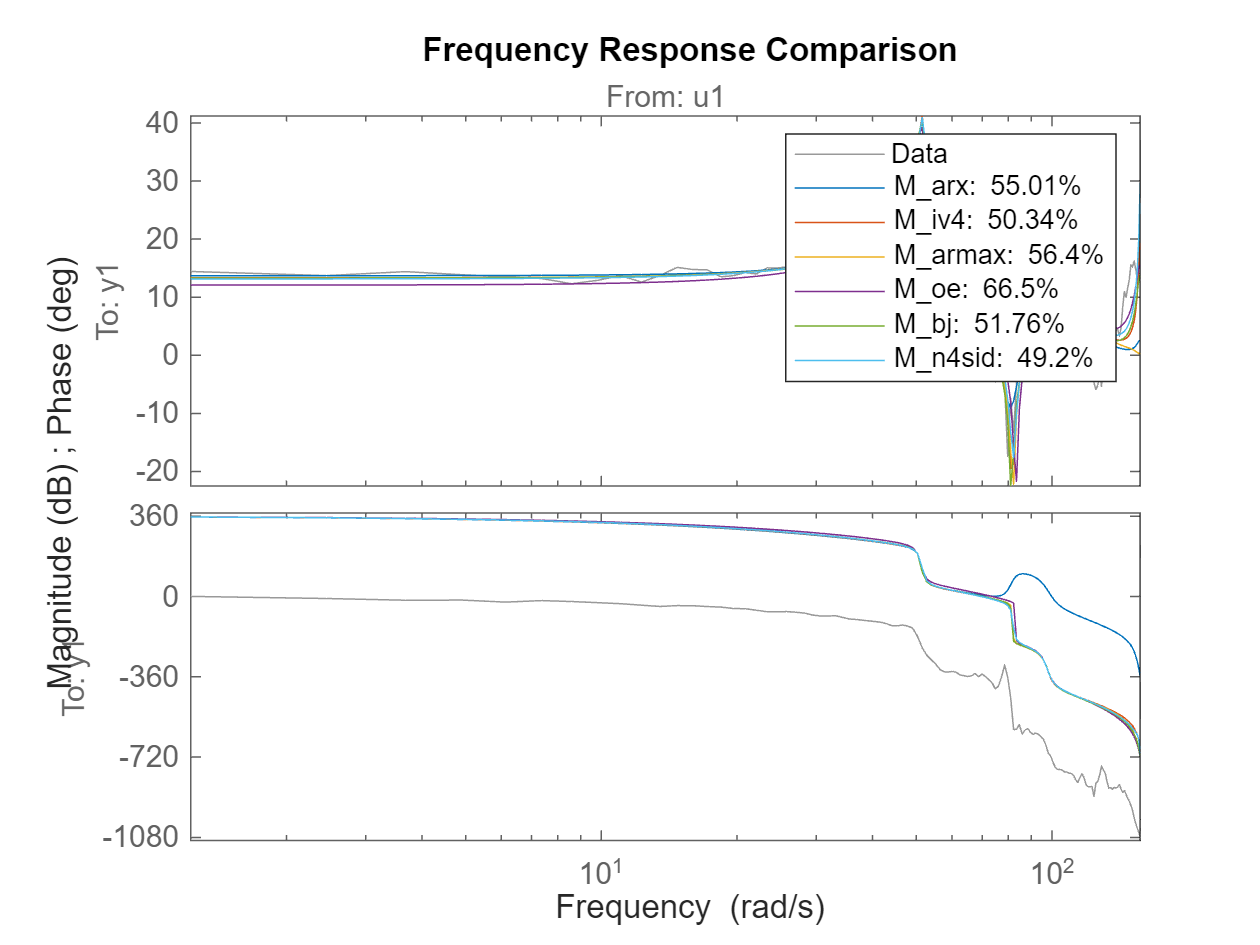

% Frequency responses vs nonparametric model (using matlab spa)
figure;
compare(frequency_response, M_arx, M_iv4, M_armax, M_oe, M_bj, M_n4sid)

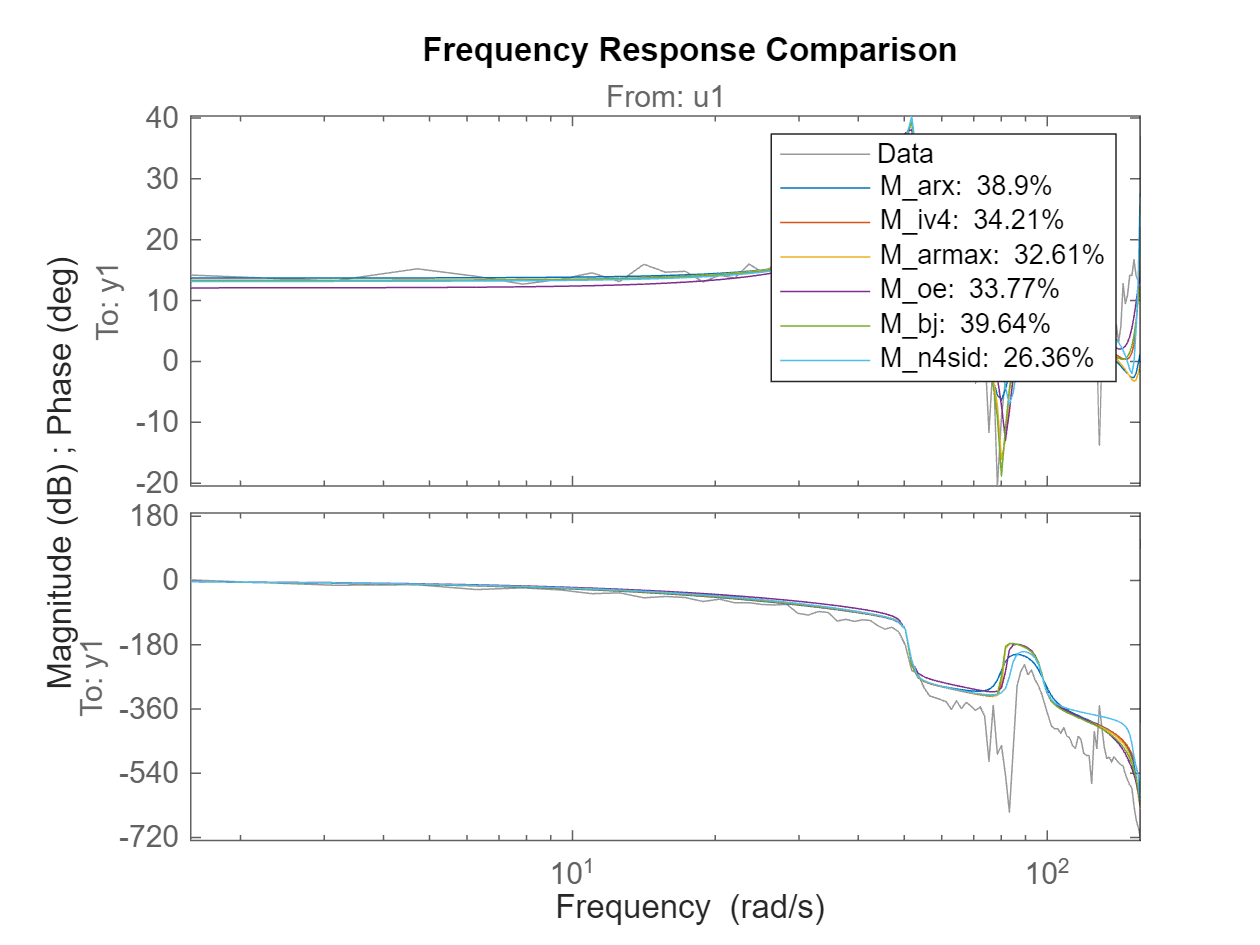


% Frequency responses vs nonparametric model (using own spectral analysis)
figure;
compare(freq_domain_model_avg', M_arx, M_iv4, M_armax, M_oe, M_bj, M_n4sid)

To compare the model in the frequency domain, the function compare() is also used. We can see that (TODO: compare models). This analysis is (TODO: compliant or not) for both of nonparametric models we identified (from matlab spa and from our own spectral analysis).

(TODO: add the graph of freq domain valid)

(TODO: verify the fit on the graph with a zoom: fit of curve, delay, noise reproduction, fit criterion)

### Statistical validaiton

% Compute Residuals for Whiteness test
fprintf("Whiteness OE")

Whiteness OE

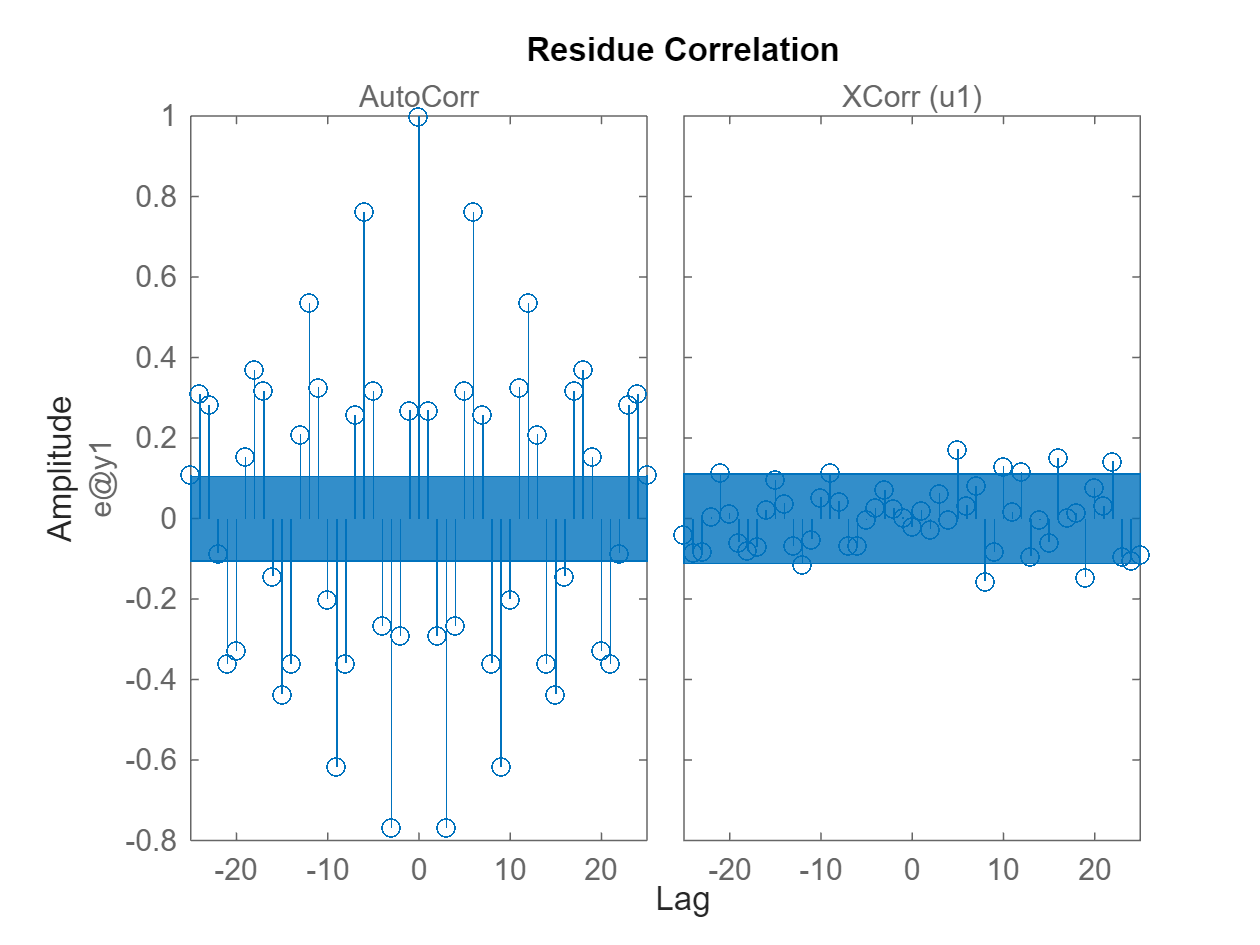

resid(Z_validation, M_oe) % No Noise model


fprintf("Whiteness IV4")

Whiteness IV4

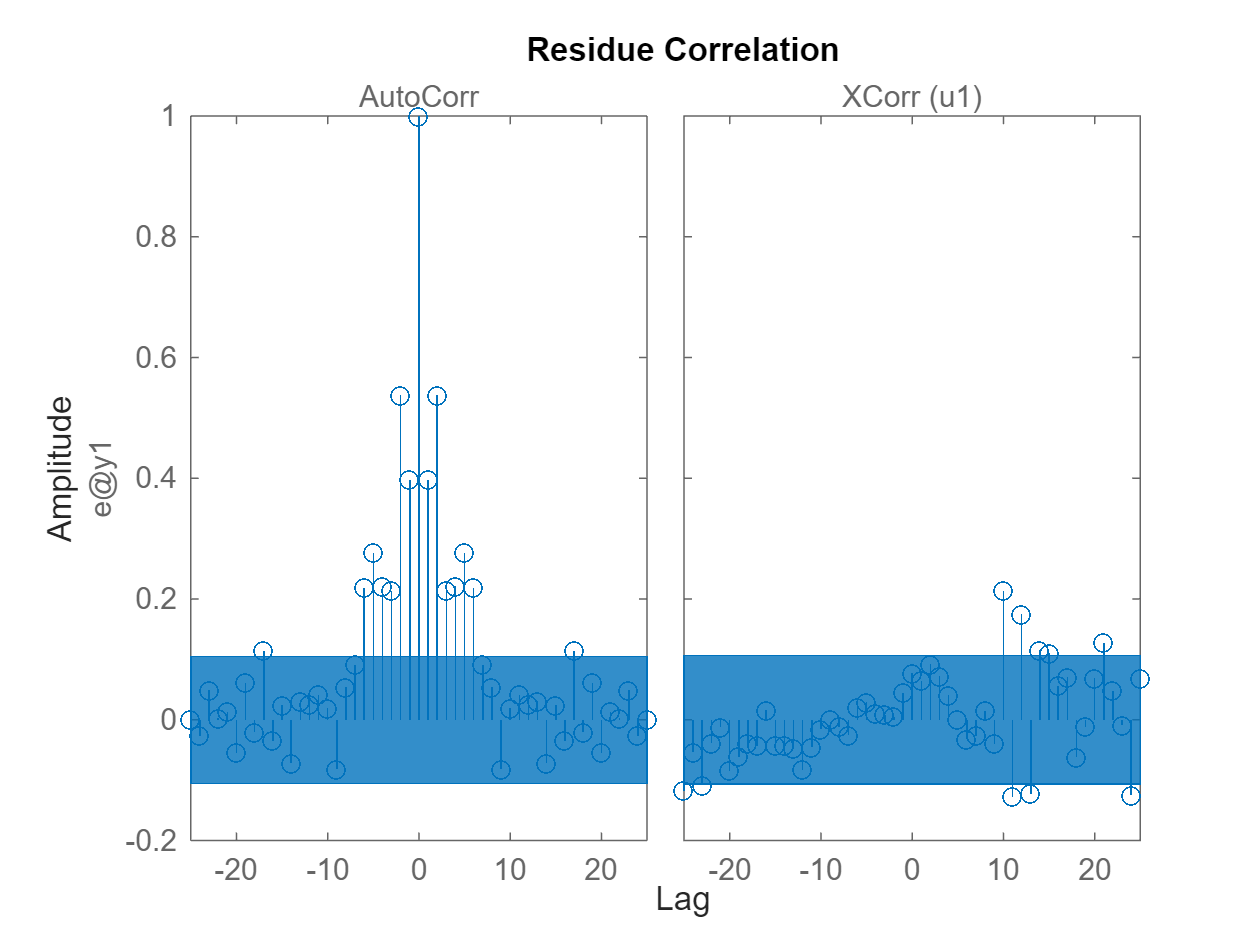

resid(Z_validation, M_iv4) % Noise model


fprintf("Whiteness ARMAX")

Whiteness ARMAX

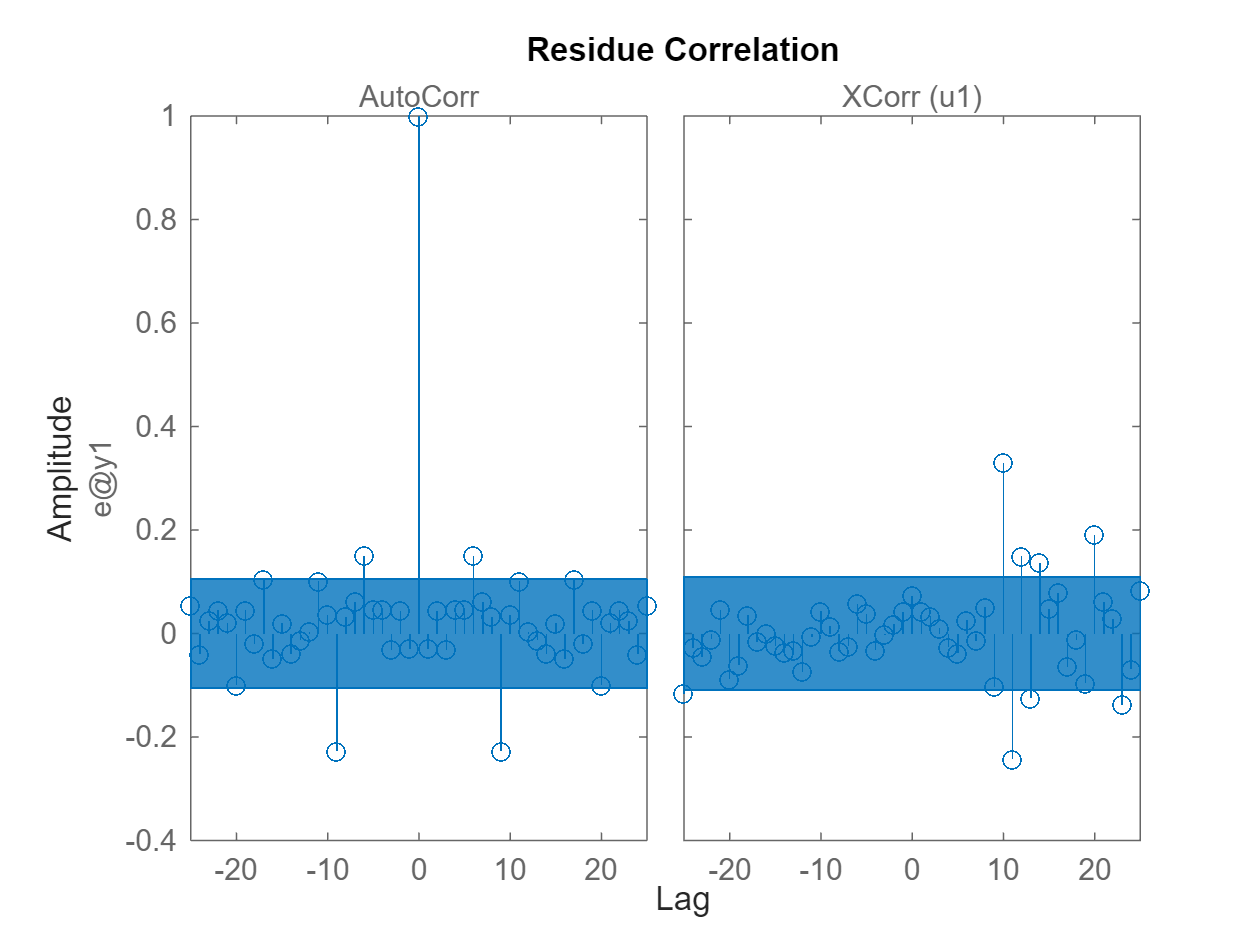

resid(Z_validation, M_armax) %  Noise model


fprintf("Whiteness ARX") 

Whiteness ARX

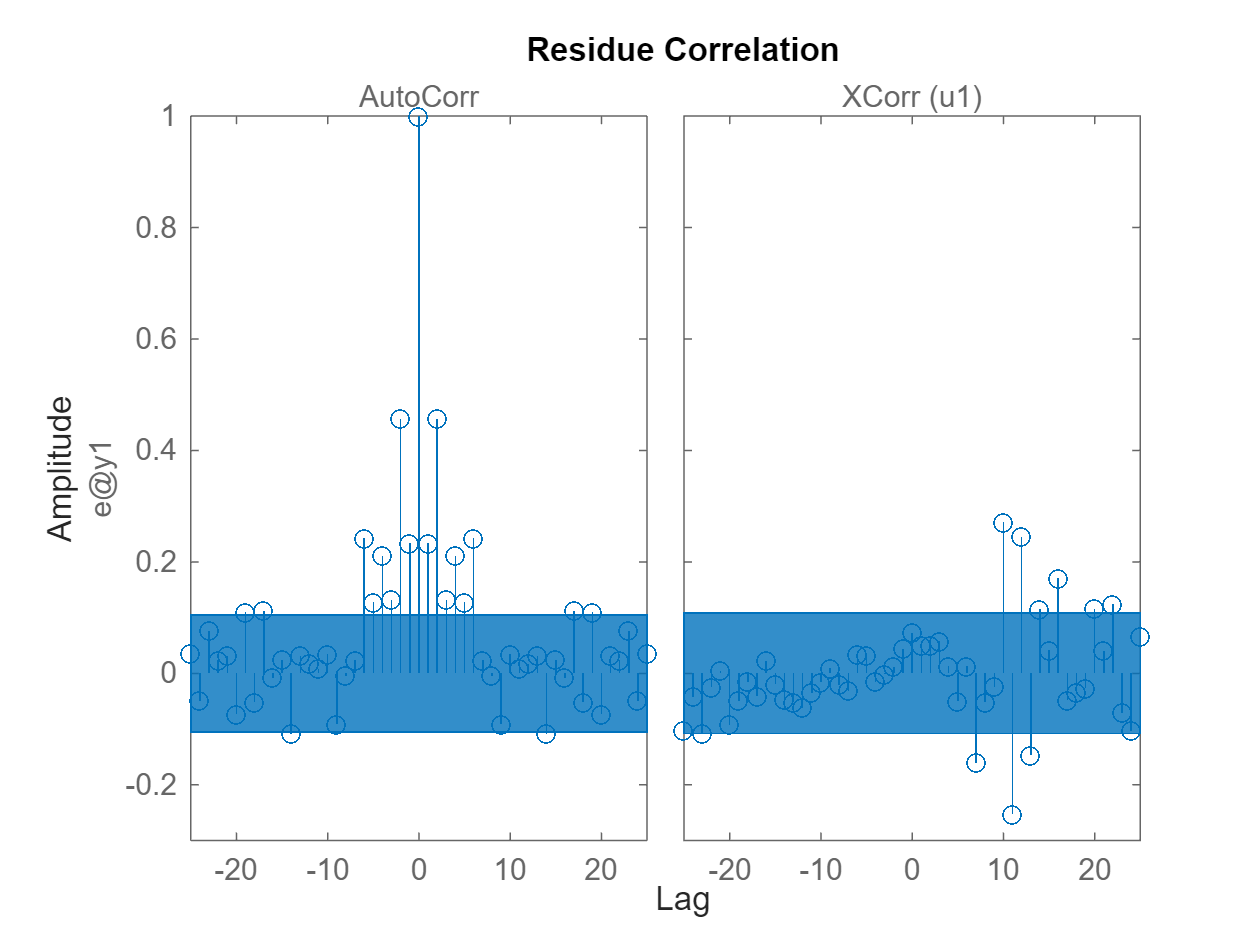

resid(Z_validation, M_arx) %  Noise model


fprintf("Whiteness BJ")

Whiteness BJ

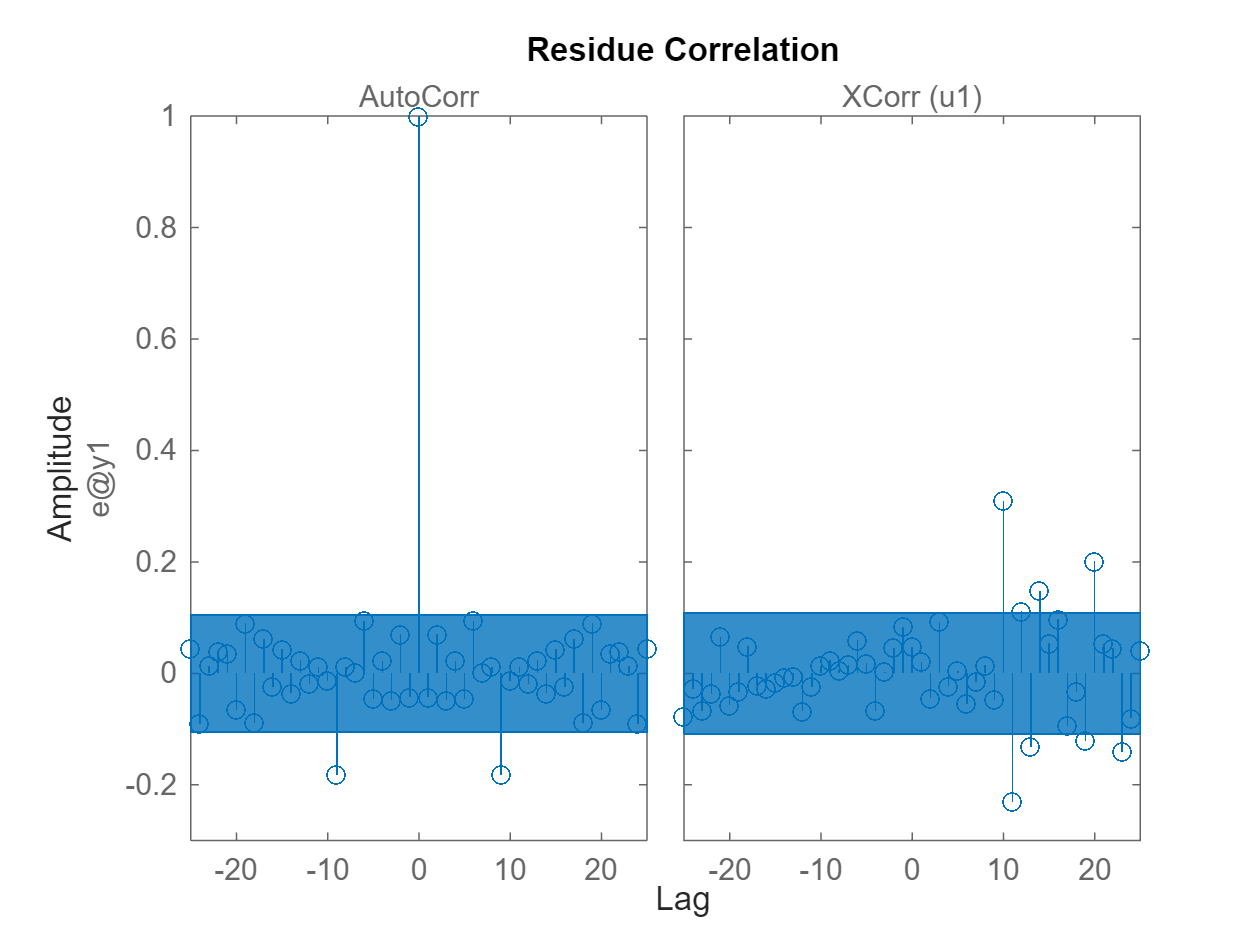

resid(Z_validation, M_bj) %  Noise model


fprintf("Whiteness N4SID")

Whiteness N4SID

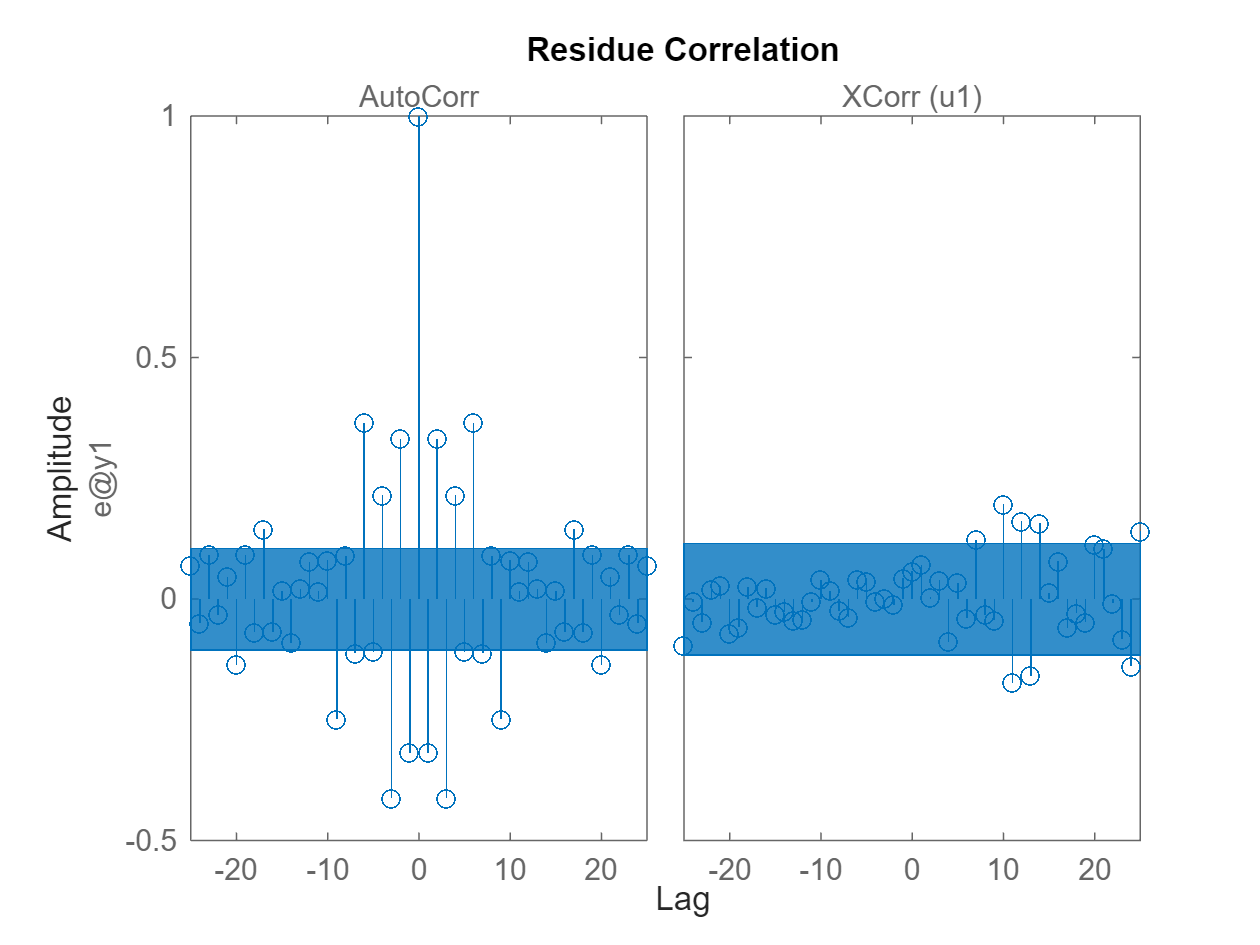

resid(Z_validation, M_n4sid) % Noise model

(TODO: add graphs of residual analyzis)

To validate the model in a more accurate way, statistical validation is performed. The following graphs show the intercorrelation of the residual with the input (right side) to validate the plant model, and the autocorrelation or whiteness test analyzes the noise of the model (left side). The left graphs are therefore irrelevant for structure without noise model. (TODO: If closed-loop, cross-correlation is irrelevant)

(TODO ARX-ARMAX-BJ-N4SID-IV-OE) are passing the intercorrelation test meaning that the plant model is well represented. Moreover, since IV and OE are in the range, we can deduce that the noise model is not compulsory.

Since (TODO ARX-ARMAX-BJ-N4SID) are passing the autocorrelation test, we can deduce that the noise is white and well modelized. Which is not the case for (TODO ARX-ARMAX-BJ-N4SID). This criterion is not verified for IV and OE since they do not implement a noise model such that this test is irrelevant.

Then we can deduce that the best model is: (TODO ARX-ARMAX-BJ-N4SID-IV-OE)

### Variance:

%Compare variance if several good model, compare for A B and F 
%Activation of the model from which you want the informations:
arx_bool = true;
iv4_bool = true;
armax_bool = true;
oe_bool = true;
bj_bool = true;
n4sid_bool = true;

if arx_bool
    present(M_arx)
end

M_arx =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                                                                                             
  A(z) = 1 + 0.2338 (+/- 0.01523) z^-1 + 0.555 (+/- 0.01384) z^-2 + 0.5519 (+/- 0.01448) z^-3 + 0.3286 (+/- 0.0137) z^-4 + 0.5033 (+/- 0.01439) z^-5 - 0.2858 (+/- 0.01099) z^-6
                                                                                                                                                                                
  B(z) = 0.4214 (+/- 0.06183) z^-2 + 3.401 (+/- 0.0622) z^-3 + 3.871 (+/- 0.08037) z^-4 + 3.371 (+/- 0.08912) z^-5 + 2.896 (+/- 0.08654) z^-6                                   
                                                                                                                                                                                
Sample time: 0.02 seconds
  
Parameterization:
   Polynomial orders:   na=6   nb=5   nk=2
   Number of free

if iv4_bool
    present(M_iv4)
end

M_iv4 =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                                                                                              
  A(z) = 1 + 0.3497 (+/- 0.02221) z^-1 + 0.6223 (+/- 0.01694) z^-2 + 0.6239 (+/- 0.02668) z^-3 + 0.3533 (+/- 0.01873) z^-4 + 0.6534 (+/- 0.02141) z^-5 - 0.292 (+/- 0.01474) z^-6
                                                                                                                                                                                 
  B(z) = 0.336 (+/- 0.06024) z^-2 + 3.452 (+/- 0.06258) z^-3 + 4.221 (+/- 0.09864) z^-4 + 3.854 (+/- 0.07193) z^-5 + 3.488 (+/- 0.09127) z^-6                                    
                                                                                                                                                                                 
Sample time: 0.02 seconds
  
Parameterization:
   Polynomial orders:   na=6   nb=5   nk=2
   Number of

if armax_bool
    present(M_arx)
end

M_arx =
Discrete-time ARX model: A(z)y(t) = B(z)u(t) + e(t)                                                                                                                             
  A(z) = 1 + 0.2338 (+/- 0.01523) z^-1 + 0.555 (+/- 0.01384) z^-2 + 0.5519 (+/- 0.01448) z^-3 + 0.3286 (+/- 0.0137) z^-4 + 0.5033 (+/- 0.01439) z^-5 - 0.2858 (+/- 0.01099) z^-6
                                                                                                                                                                                
  B(z) = 0.4214 (+/- 0.06183) z^-2 + 3.401 (+/- 0.0622) z^-3 + 3.871 (+/- 0.08037) z^-4 + 3.371 (+/- 0.08912) z^-5 + 2.896 (+/- 0.08654) z^-6                                   
                                                                                                                                                                                
Sample time: 0.02 seconds
  
Parameterization:
   Polynomial orders:   na=6   nb=5   nk=2
   Number of free

if oe_bool
    present(M_oe)
end

M_oe =
Discrete-time OE model: y(t) = [B(z)/F(z)]u(t) + e(t)                                                                                                                            
  B(z) = 0.487 (+/- 0.07381) z^-2 + 3.533 (+/- 0.08105) z^-3 + 4.809 (+/- 0.103) z^-4 + 4.124 (+/- 0.1082) z^-5 + 3.711 (+/- 0.08582) z^-6                                       
                                                                                                                                                                                 
  F(z) = 1 + 0.4947 (+/- 0.01895) z^-1 + 0.7605 (+/- 0.0146) z^-2 + 0.7299 (+/- 0.01701) z^-3 + 0.5333 (+/- 0.01703) z^-4 + 0.7404 (+/- 0.01362) z^-5 - 0.1096 (+/- 0.01796) z^-6
                                                                                                                                                                                 
Sample time: 0.02 seconds
  
Parameterization:
   Polynomial orders:   nb=5   nf=6   nk=2
   Number of 

if bj_bool
    present(M_bj)
end

M_bj =
Discrete-time BJ model: y(t) = [B(z)/F(z)]u(t) + [C(z)/D(z)]e(t)                                                                                                                      
  B(z) = 0.4688 (+/- 0.04443) z^-2 + 3.391 (+/- 0.04638) z^-3 + 4.249 (+/- 0.05976) z^-4 + 3.749 (+/- 0.05233) z^-5 + 3.416 (+/- 0.05392) z^-6                                        
                                                                                                                                                                                      
  C(z) = 1 - 0.2553 (+/- 0.06205) z^-1 + 0.5047 (+/- 0.0552) z^-2 - 0.3827 (+/- 0.07174) z^-3 + 0.07015 (+/- 0.05957) z^-4 + 0.0006913 (+/- 0.04643) z^-5 + 0.05976 (+/- 0.04168) z^-6
                                                                                                                                                                                      
  D(z) = 1 - 0.2192 (+/- 0.0573) z^-1 + 0.4403 (+/- 0.04905) z^-2 + 0.07048 (+

if n4sid_bool
    present(M_n4sid)
end

M_n4sid =
  Discrete-time identified state-space model:
    x(t+Ts) = A x(t) + B u(t) + K e(t)
       y(t) = C x(t) + D u(t) + e(t)
 
  A = 
                            x1                       x2                       x3                       x4                       x5                       x6
   x1     0.5094 +/- 6.496e+12     0.8425 +/- 6.458e+12    0.04557 +/-   1.6e+13   -0.04933 +/- 1.377e+13   -0.04067 +/- 1.393e+13    -0.1004 +/- 1.034e+13
   x2    -0.8409 +/- 5.986e+12     0.5311 +/- 7.101e+12   -0.04228 +/- 2.746e+13     0.0711 +/- 1.826e+13    0.02729 +/- 1.704e+13    0.05568 +/- 1.012e+13
   x3   0.002362 +/- 9.636e+13  -0.005872 +/- 8.561e+13    -0.9294 +/- 1.127e+13    -0.2815 +/- 4.279e+13    0.06537 +/- 4.323e+13    -0.1841 +/- 3.766e+13
   x4    0.02821 +/- 5.469e+13    0.02992 +/- 6.083e+13     0.1204 +/- 3.881e+13    -0.3283 +/- 2.102e+13     0.9317 +/- 1.872e+13    0.03581 +/- 3.005e+13
   x5  -0.004457 +/- 4.847e+13    0.02962 +/- 5.259e+13    0.04612 +/- 3.088e+1

Several models seems to fit the previous criterions, then we can compare the variance of the parameters to choose the best model. Between the variance of the following models: (TODO ARX-ARMAX-BJ-N4SID-IV-OE), we can deduce that the best model is: (TODO ARX-ARMAX-BJ-N4SID-IV-OE).

# Function Definition

function plot_input_output_signals(u, y)
% All timesteps
figure;
plot(u)
xlabel("Time steps (k)")
ylabel("Input Magnitude")
title("Input signal")
xlim([0, length(u)])

% Only few
figure;
stem(u)
xlabel("Time steps (k)")
ylabel("Input Magnitude")
title("Input signal (k=0 to k=100)")
xlim([0, 100])

% Plot output signal
% All timesteps
figure;
plot(y)
xlabel("Time steps (k)")
ylabel("Output Magnitude")
title("Output signal")
xlim([0, length(y)])

% Only few
figure;
plot(y)
xlabel("Time steps (k)")
ylabel("Output Magnitude")
title("Output signal (k=0 to k=100)")
xlim([0, 100])
end



function [freq_resp] = spa_premium(data, apply_windowing, window_size, apply_averaging, nb_groups)
    N = length(data.y);
    if apply_windowing
        freq_resp = spa(data, window_size);
        disp("Performing Windowed Spectral Analysis with Hann window of size " + num2str(window_size) + "...")
    elseif apply_averaging
        freq_resp = spa(data, N/nb_groups, [], N/nb_groups);
        disp("Performing Averaged Spectral Analysis with " + num2str(nb_groups) + " groups of size " + num2str(N/nb_groups) + "...")
    else
        freq_resp = spa(data);
        disp("Performing basic Spectral Analysis...")
    end
end




function [R_uy,hh] = intcor(u,y)
    M = length(u);
    R_uy = zeros(M,1);
    hh = 0:1:M-1;
    for h = 0:1:M-1
        for k = 1:1:M
            % Taking care of periodicity
            index = k-h;
            if index <= 0
                index = M + index;
            end
            R_uy(h+1) = R_uy(h+1) + u(k)*y(index)/M;
        end
    end
    R_uy = [flip(R_uy(2:end)); R_uy]';
    hh = [flip(-hh(2:end)),hh];
end